# ECE 808 Smart Water Networks (Lecture 2)

## Research tools for Smart Water Networks

### **Different types of uncertainties**

- Uniform, fixed bounds, good when we don't know reality

- Normal distribution, unbounded, good if we know distribution is normal. WARNING! Not all non-uniform distributions are normal!

N = 100000

N = 100000

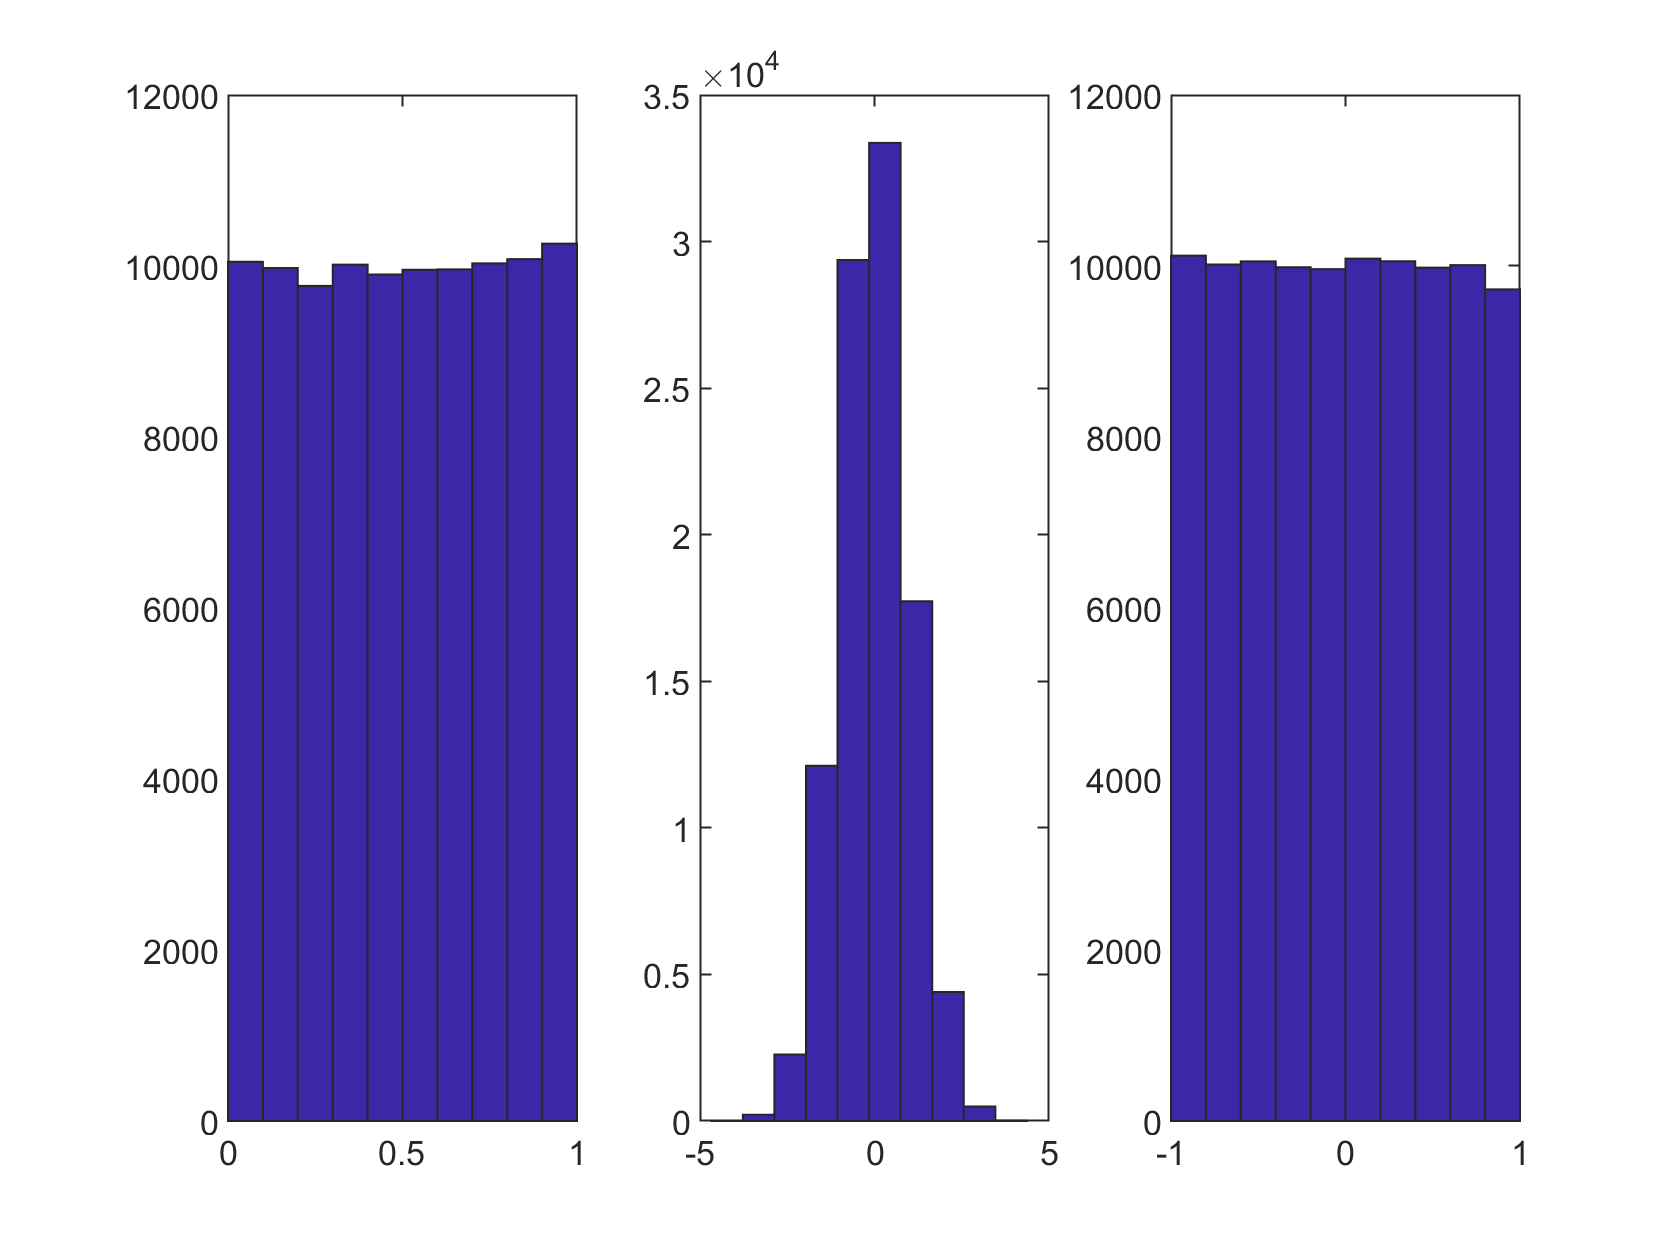

unif_rand = rand(N,1); %[0,1]
norm_rand = randn(N,1); % any real number
unif_rand2 = 2*rand(N,1)-1; %[-1,1]
figure
subplot(1,3,1)
hist(unif_rand)
subplot(1,3,2)
hist(norm_rand)
subplot(1,3,3)
hist(unif_rand2)

How to randomize a vector $a$ with a bounded uncertainty ?

$a'=a+\eta a = (1+\eta) a$ , where $|\eta| < \bar{\eta}$ is the uncertainty

a = [8 8 6 10 12]

a =      8     8     6    10    12


eta_bar = 0.2 % max uncertainty 20%

eta_bar = 0.2000

eta = (2*rand(1,length(a))-1)*eta_bar.*a

eta =    -1.0021   -1.2854   -0.2574    1.7083    1.7273


a2 = a + eta

a2 =     6.9979    6.7146    5.7426   11.7083   13.7273


**For non-random pseuso-random numbers, use RNG function! Useful for reproducing results.**

rng(20)
a = [8 8 6 10 12]

a =      8     8     6    10    12


eta_bar = 0.2 % max uncertainty 20%

eta_bar = 0.2000

eta = (2*rand(1,length(a))-1)*eta_bar.*a

eta =     0.2820    1.2727    0.9397    1.2633   -2.2277


a2 = a + eta

a2 =     8.2820    9.2727    6.9397   11.2633    9.7723


### **Monte Carlo Simulations for EPANET **

How does uncertainty in the base demands, affects the pressures in a network?

Useful for:

- Fault diagnosis

- State estimation

- Forecasting

- Sensitivity studies

- Demonstrating robustness of solutions

**Initialize EPANET**

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


**Prepare network for Monte Carlo Simulations**

% Load network
G = epanet('net2-cl2.inp')

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "net2-cl2.inp"...
Input File "net2-cl2.inp" loaded sucessfuly.


G =   epanet with properties:

                   ControlLevelValues: []
                     ControlLinkIndex: []
                     ControlNodeIndex: []
                         ControlRules: []
                    ControlRulesCount: 0
                             Controls: [1×1 struct]
                      ControlSettings: []
                         ControlTypes: {}
                    ControlTypesIndex: []
                           CurveCount: 0
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1000
                      DemandModelPexp: 0.5000
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits: 'percent'
                          EnergyUnits: 'kwatt-hours'
                              Errcode: 0
                            InputFile: 'C:\Users\eldemet\Docum

% Number of simulations
Nsim = 50

Nsim = 50

% Get nominal base demands
base_demands = G.getNodeBaseDemands{1}

base_demands =  -694.4000    8.0000   14.0000    8.0000    8.0000    5.0000    4.0000    9.0000   14.0000    5.0000   34.7800   16.0000    2.0000    2.0000    2.0000   20.0000   20.0000   20.0000    5.0000   19.0000   16.0000   10.0000    8.0000   11.0000    6.0000    8.0000         0    7.0000    3.0000   17.0000   17.0000    1.5000    1.5000         0    1.0000         0


% 5% max uncertainty in base demands
eta_bar = 0.05

eta_bar = 0.0500


% initialize matrix to save MCS pressures
Pmcs = {};
Qmcs = {};

**Run the simulation and store the pressure results**

for i = 1:Nsim
    %compute new base demands
    delta_bd = (2*rand(1,length(base_demands))-1).*eta_bar.*base_demands;
    new_base_demands = base_demands + delta_bd;
    G.setNodeBaseDemands(new_base_demands);
    Pmcs{i} = G.getComputedHydraulicTimeSeries.Pressure;
    Qmcs{i} = G.getComputedQualityTimeSeries.NodeQuality;
    disp(['Epoch ',int2str(i)])
end

Epoch 1
Epoch 2
Epoch 3
Epoch 4
Epoch 5
Epoch 6
Epoch 7
Epoch 8
Epoch 9
Epoch 10
Epoch 11
Epoch 12
Epoch 13
Epoch 14
Epoch 15
Epoch 16
Epoch 17
Epoch 18
Epoch 19
Epoch 20
Epoch 21
Epoch 22
Epoch 23
Epoch 24
Epoch 25
Epoch 26
Epoch 27
Epoch 28
Epoch 29
Epoch 30
Epoch 31
Epoch 32
Epoch 33
Epoch 34
Epoch 35
Epoch 36
Epoch 37
Epoch 38
Epoch 39
Epoch 40
Epoch 41
Epoch 42
Epoch 43
Epoch 44
Epoch 45
Epoch 46
Epoch 47
Epoch 48
Epoch 49
Epoch 50


**How pressure fluctuates?**

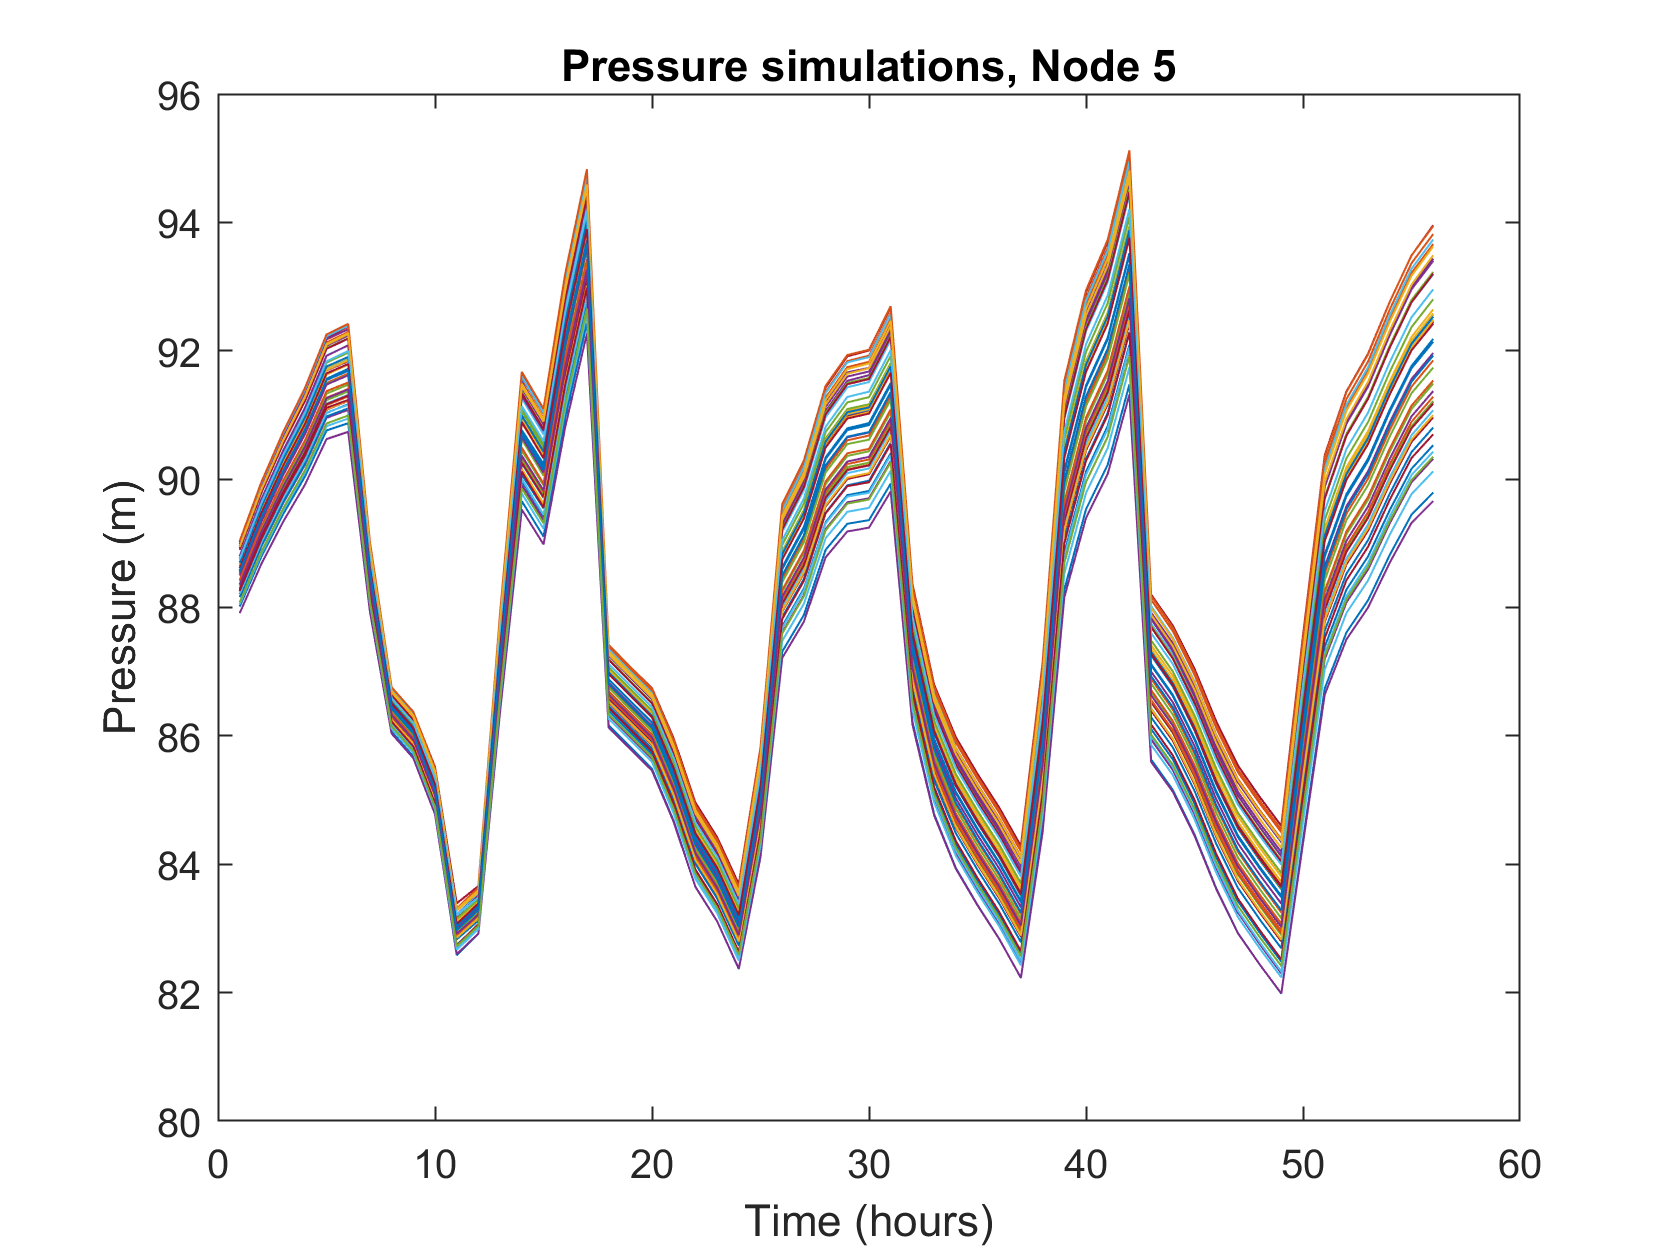

node = 5;
figure
for i = 1:Nsim
    Pmulti(:,i) = Pmcs{i}(:,node);
    plot(Pmulti(:,i))
    hold on
end
title(['Pressure simulations, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')

**Compute upper and lower bounds**

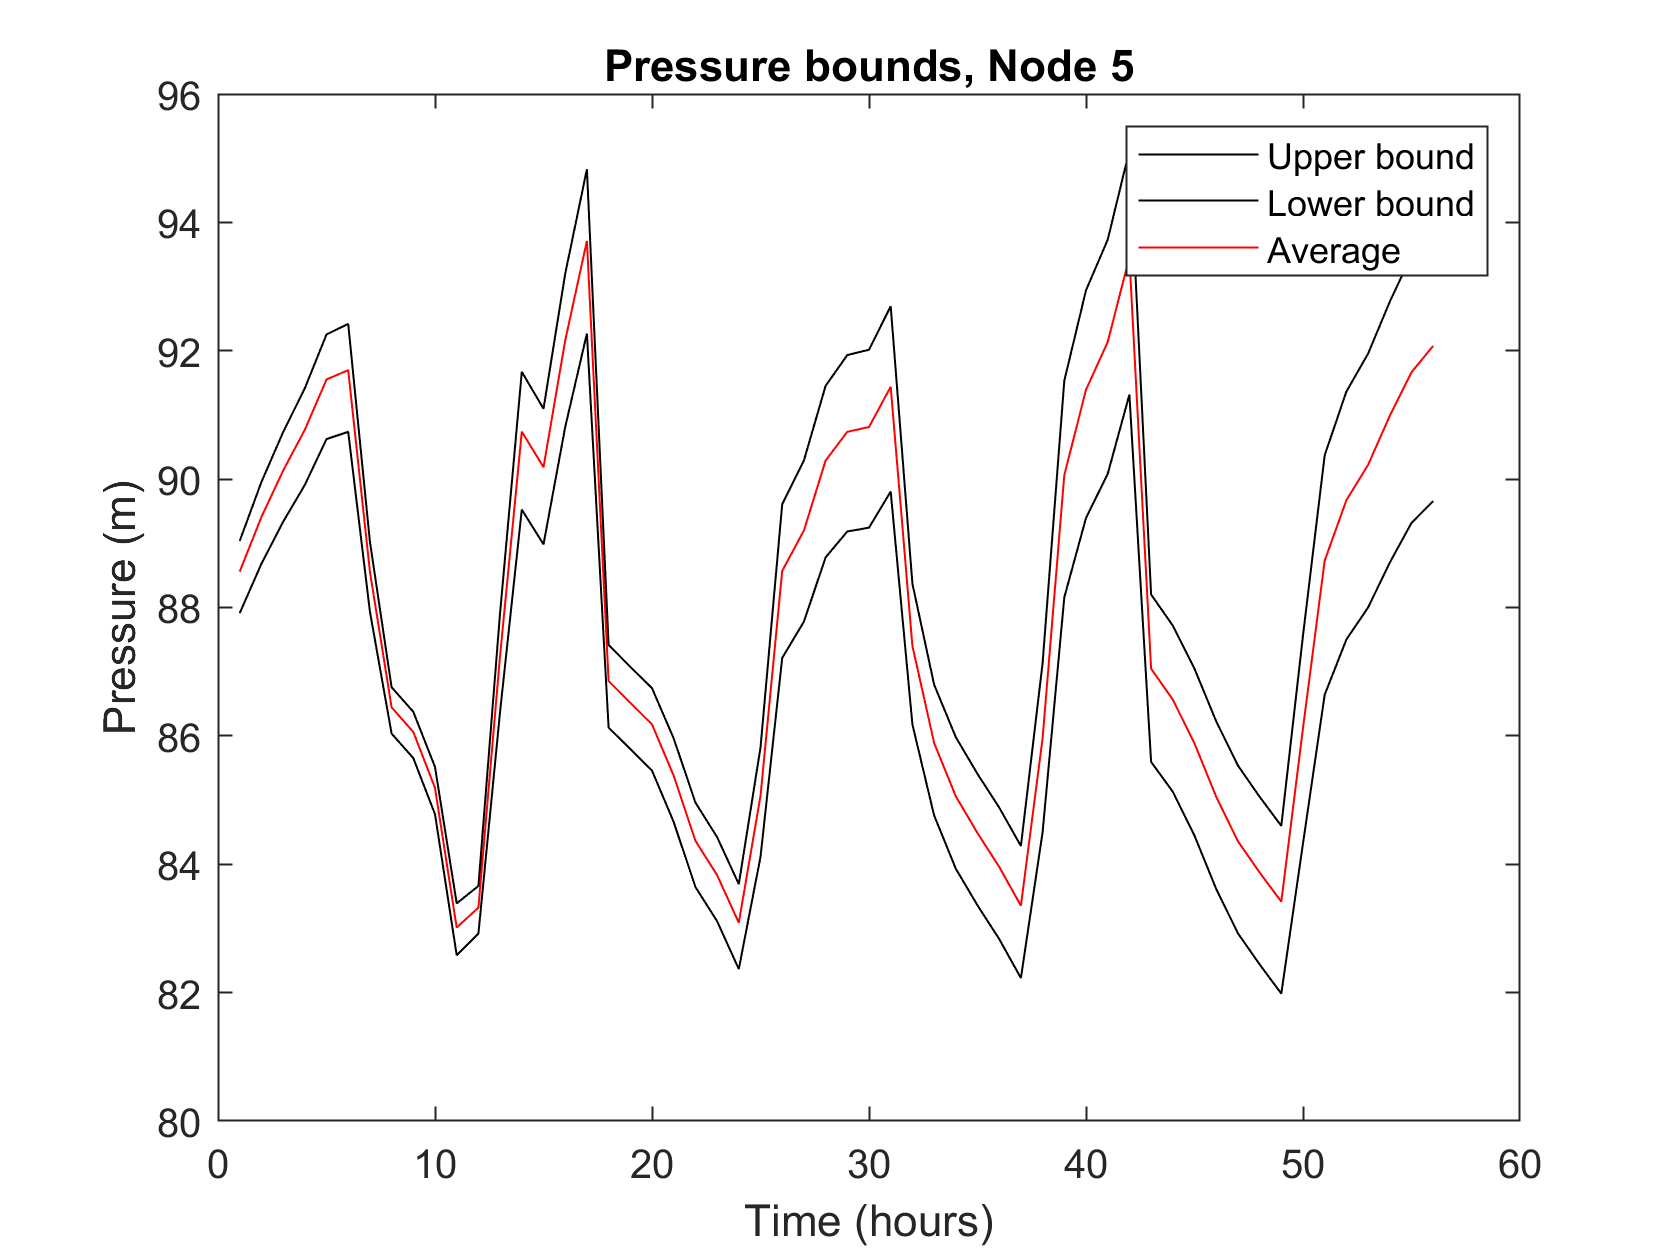

ub = max(Pmulti,[],2);
lb = min(Pmulti,[],2);
meanb = mean(Pmulti,2);

figure
plot(ub,'k')
hold on
plot(lb,'k')
plot(meanb, 'r')
legend('Upper bound','Lower bound', 'Average')
title(['Pressure bounds, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')

**How quality fluctuates?**

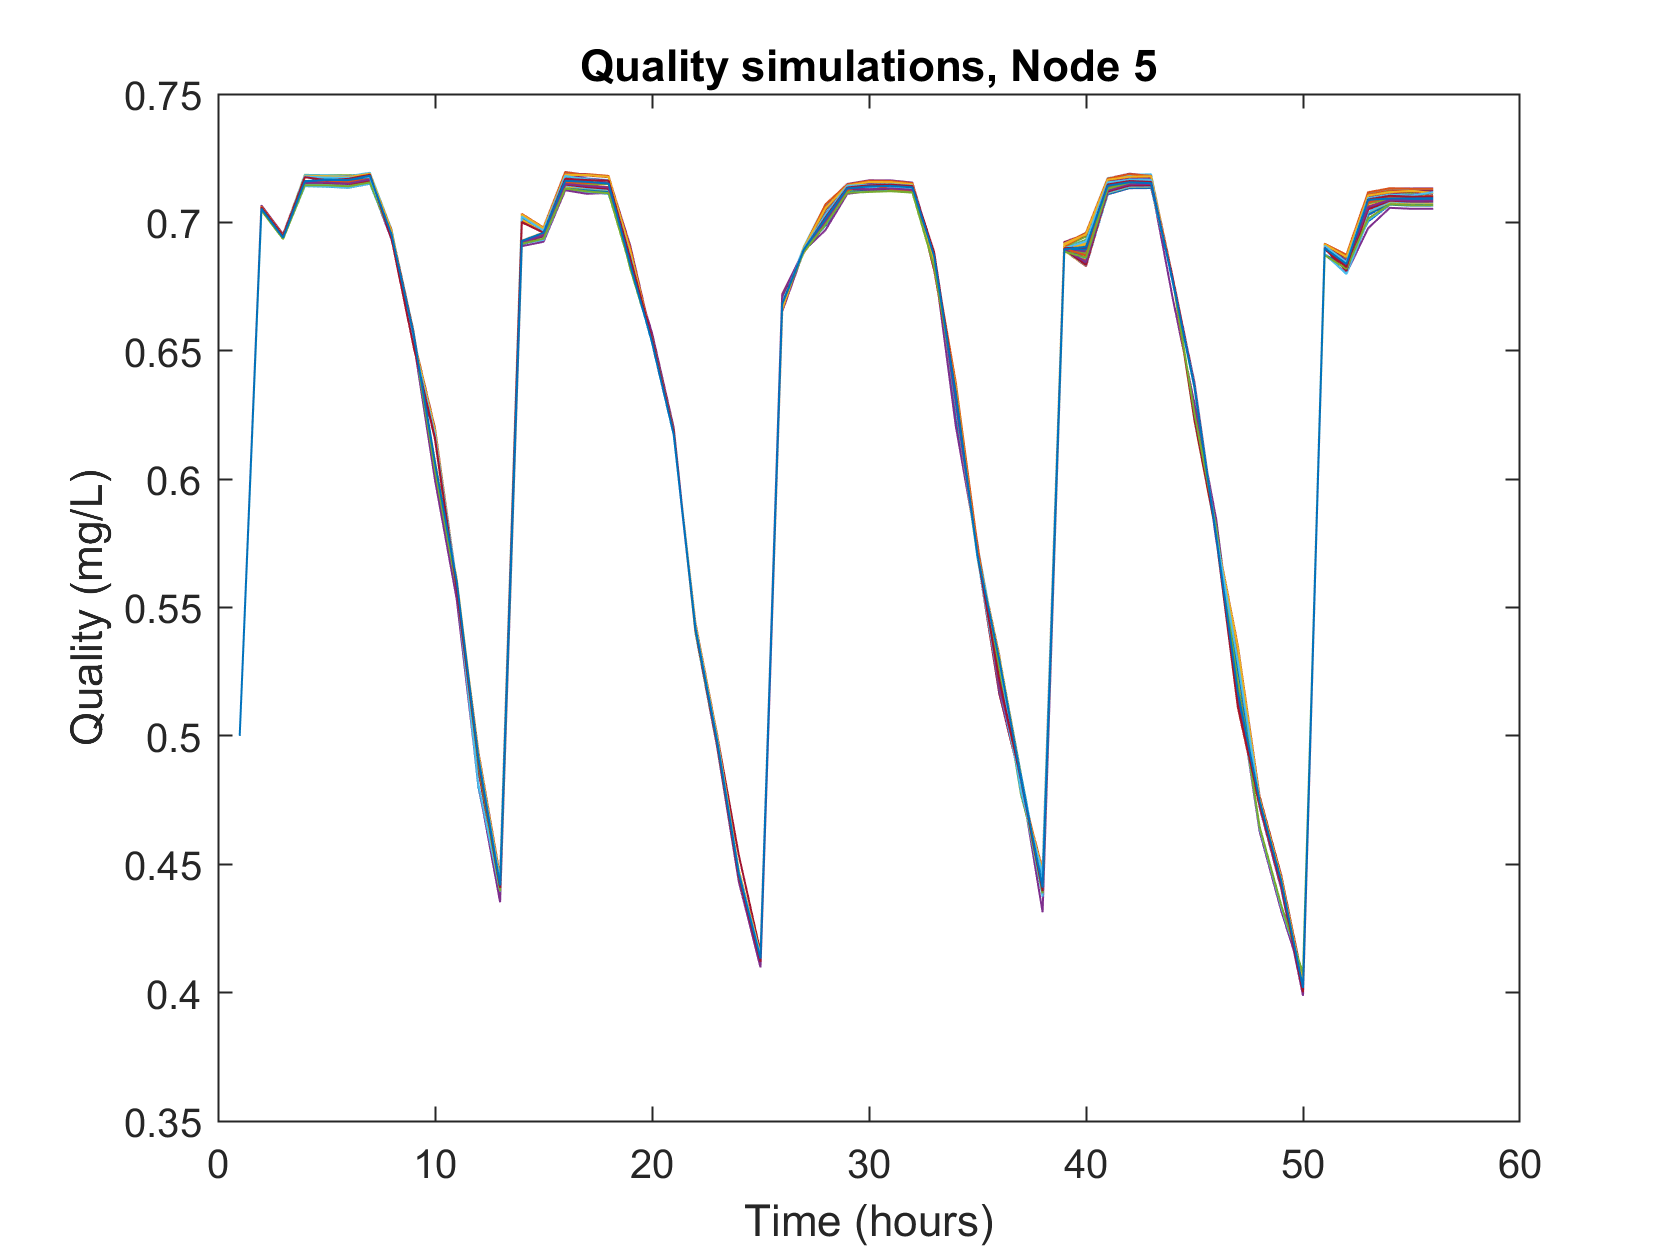

node = 5;
figure
for i = 1:Nsim
    Qmulti(:,i) = Qmcs{i}(:,node);
    plot(Qmulti(:,i))
    hold on
end
title(['Quality simulations, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Quality (mg/L)')

**Compute upper and lower bounds**

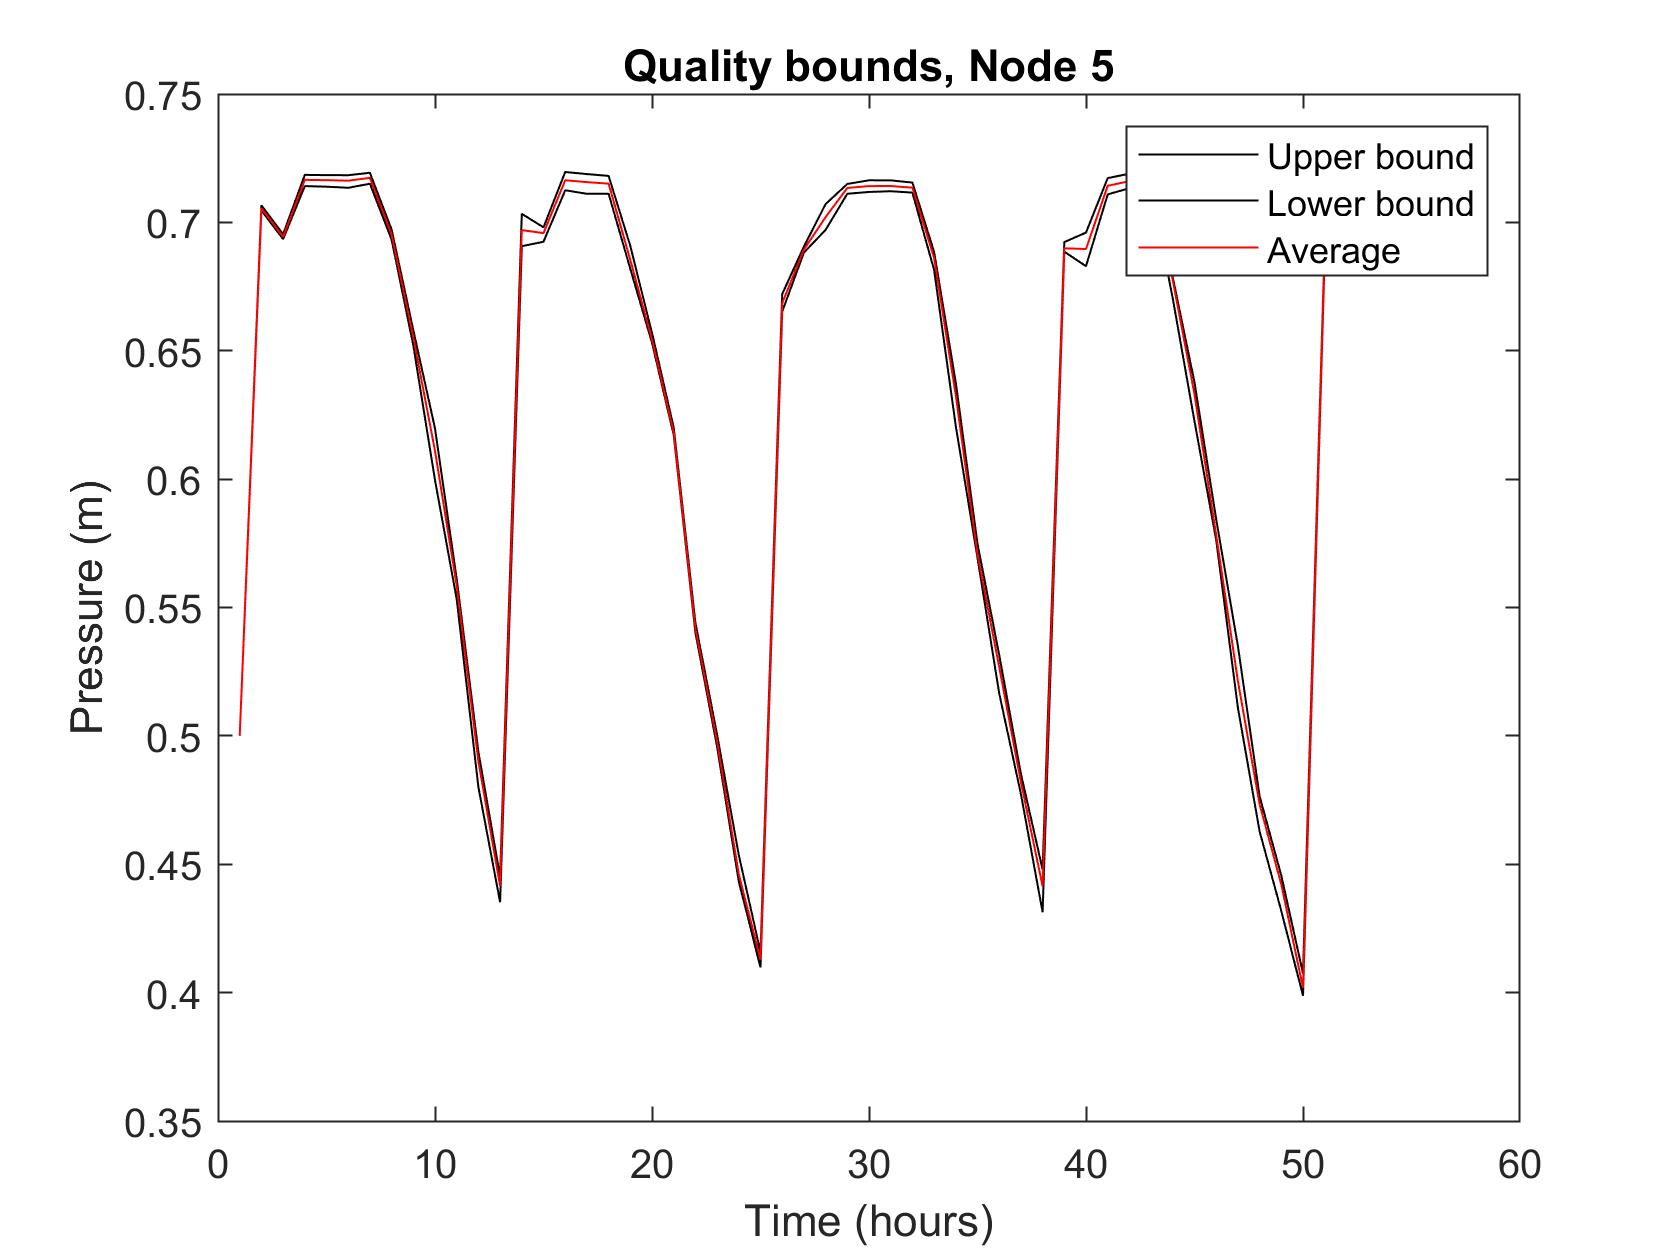

ub = max(Qmulti,[],2);
lb = min(Qmulti,[],2);
meanb = mean(Qmulti,2);

figure
plot(ub,'k')
hold on
plot(lb,'k')
plot(meanb, 'r')
legend('Upper bound','Lower bound', 'Average')
title(['Quality bounds, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')

## Solving problems using the EPANET-MATLAB Toolkit

### **Minimum Chlorine concentration for disinfection**

**WHO guidelines**

- Chlorine is added post-treatment/post source

- Maintain a residual at all points in network

- There should always be at least 0.2 mg/l free chlorine

- In time of cholera or other outbreak minimum is 0.5 mg/l in network and 1 mg/l at public standposts

- May get a reduction in residual during storage and distribution

- Therefore may need booster chlorination

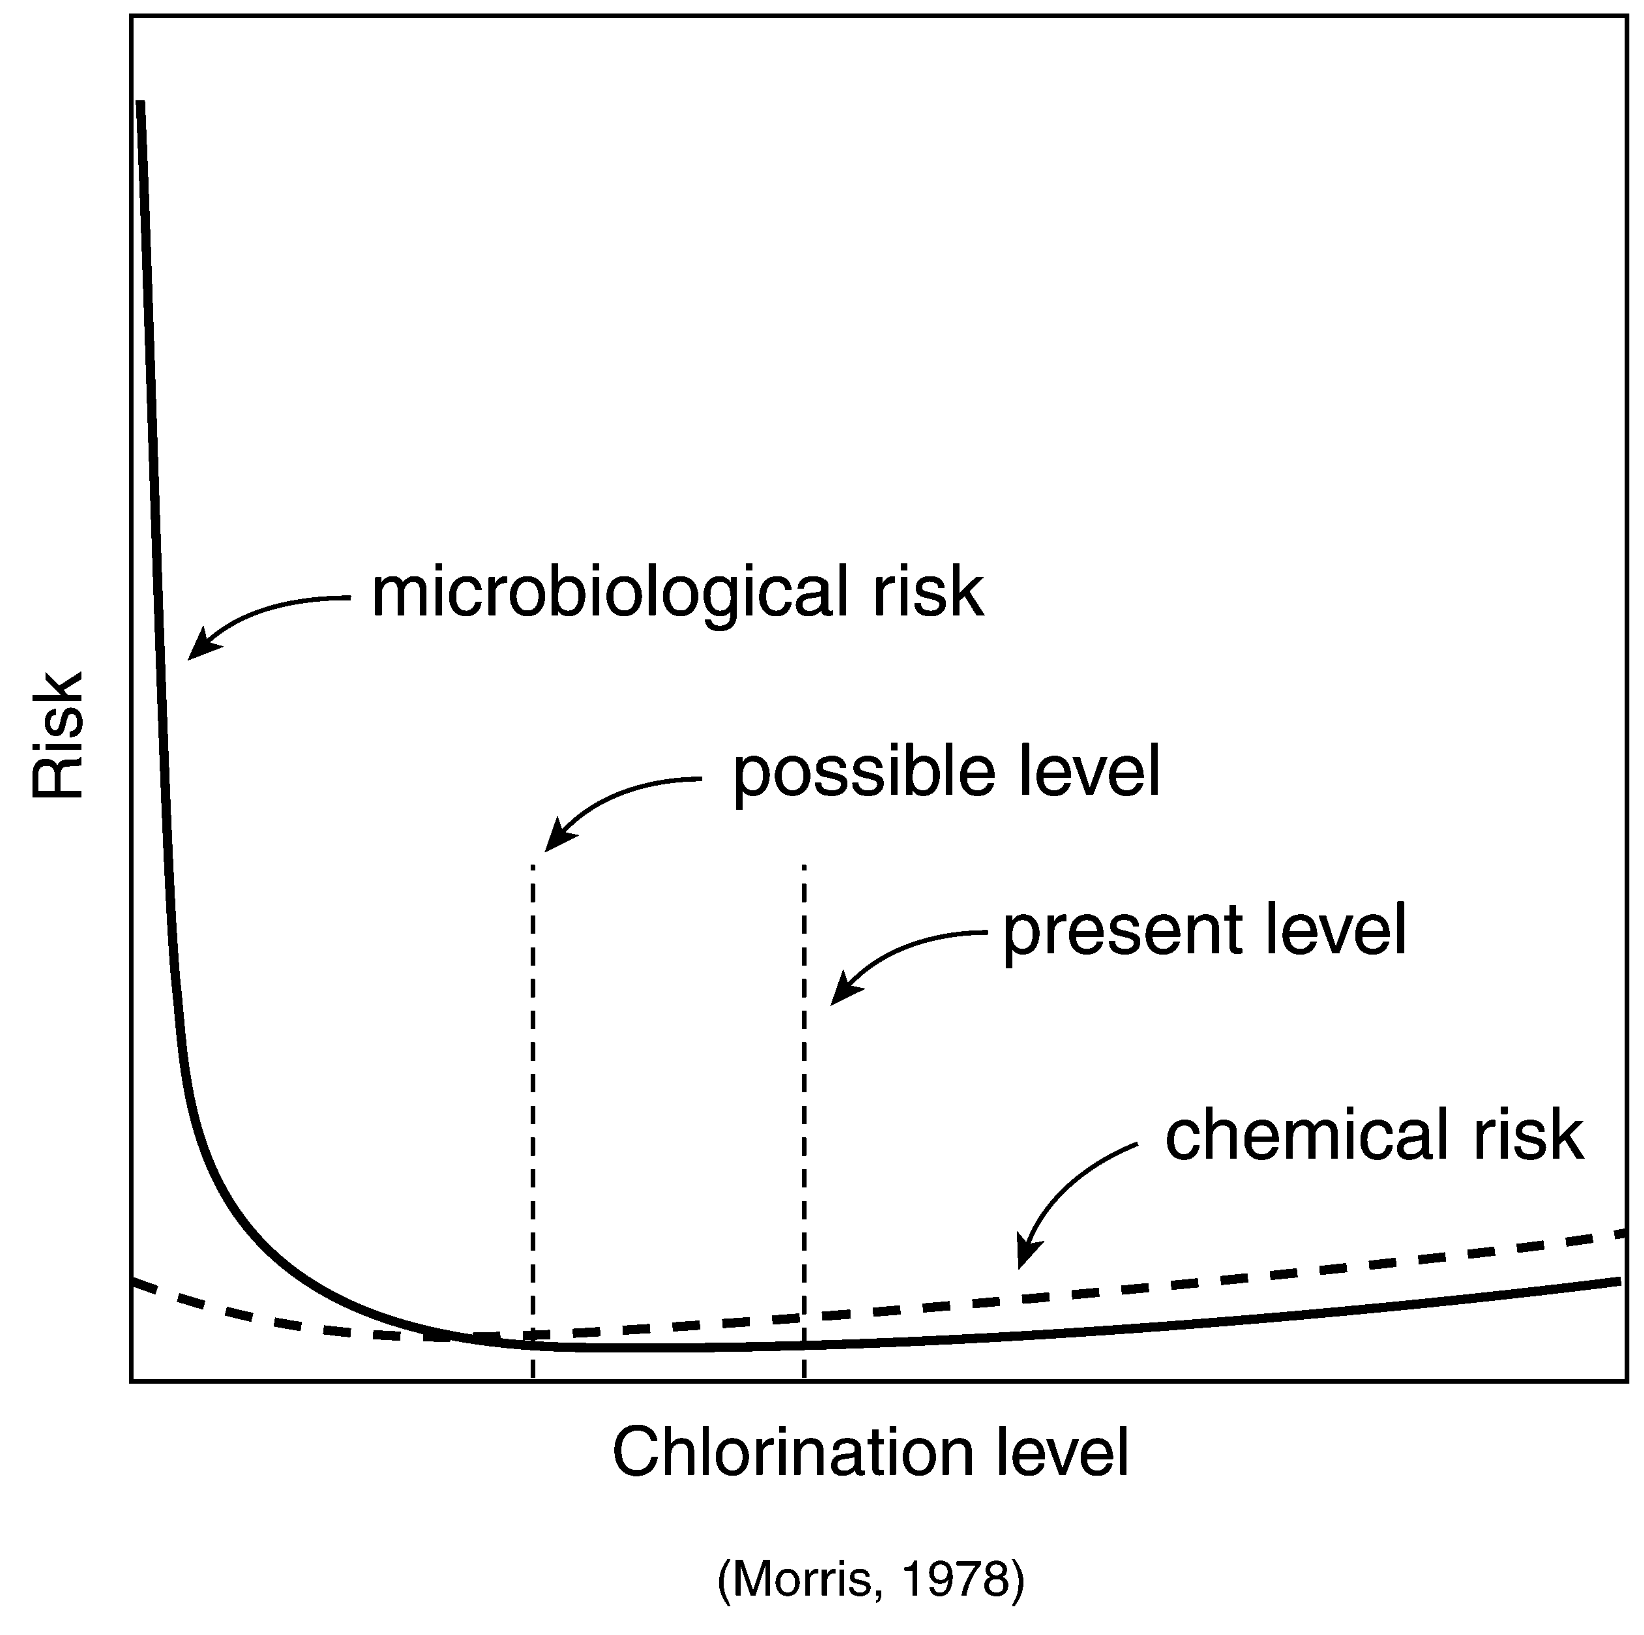

How much chlorine to inject in your system, in order to maintain a mininum concentration of 0.2 mg/L?

G = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded sucessfuly.


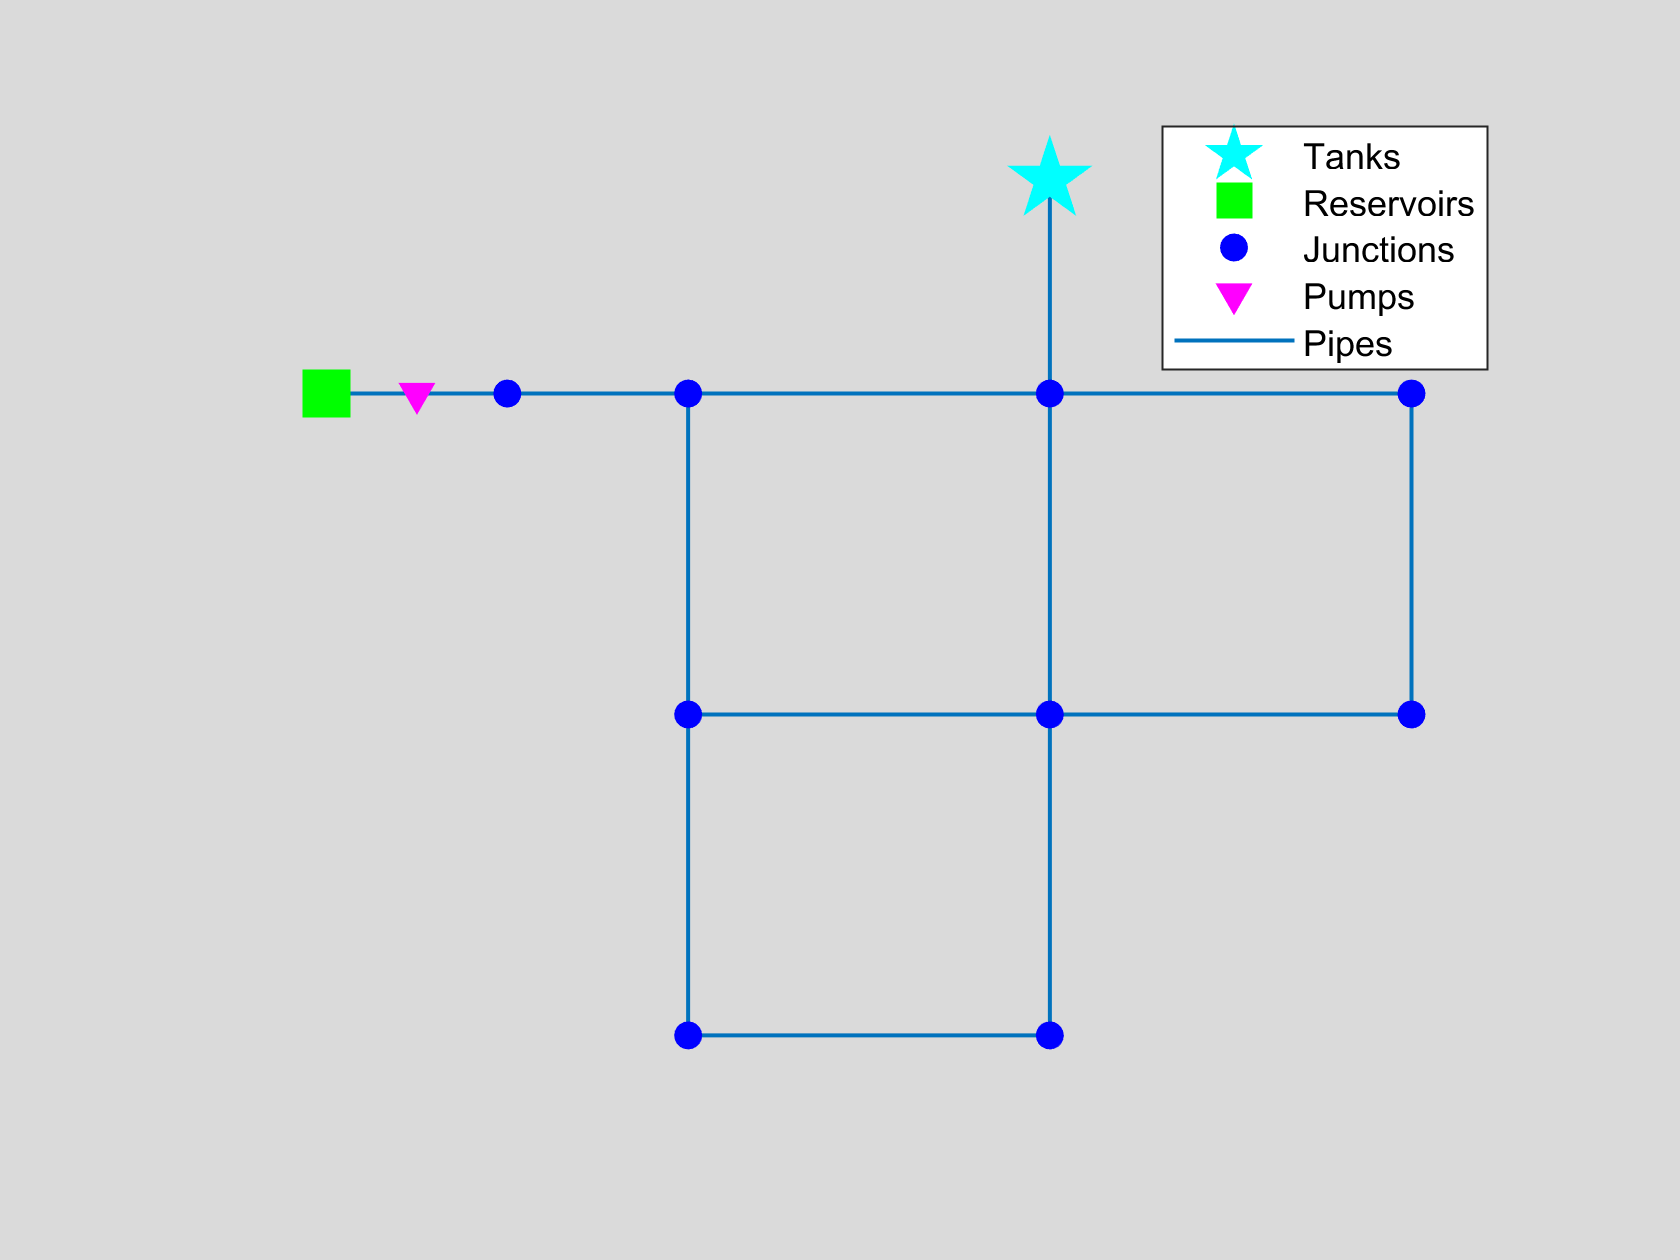

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


G.plot


SourceID = '9'; % Source node id
SimDays = 14;
G.setTimeSimulationDuration(SimDays*24*3600) % Set simulation time
Nnodes = G.getNodeCount % Get the number of nodes

Nnodes = int32
11

sourceindex = G.getNodeIndex(SourceID) % Get source node's index

sourceindex = int32
10

G.setQualityType('Chlorine', 'mg/L', '') % Setup system to analyze for chlorine (in case it was not done in the input file.)

% make all initial concentrations 0 mg/L
for i = 1:Nnodes
    G.setNodeInitialQuality(i,0)
end

**Let's try a random concentration**

cl2_conc = 4.6 % mg/L

cl2_conc = 4.6000

G.setNodeSourceQuality(sourceindex, cl2_conc);
Q = G.getComputedQualityTimeSeries.NodeQuality;
minQ = min(Q,[],2);
minCl2 = min(minQ((end-24):end))

minCl2 = 0.3642

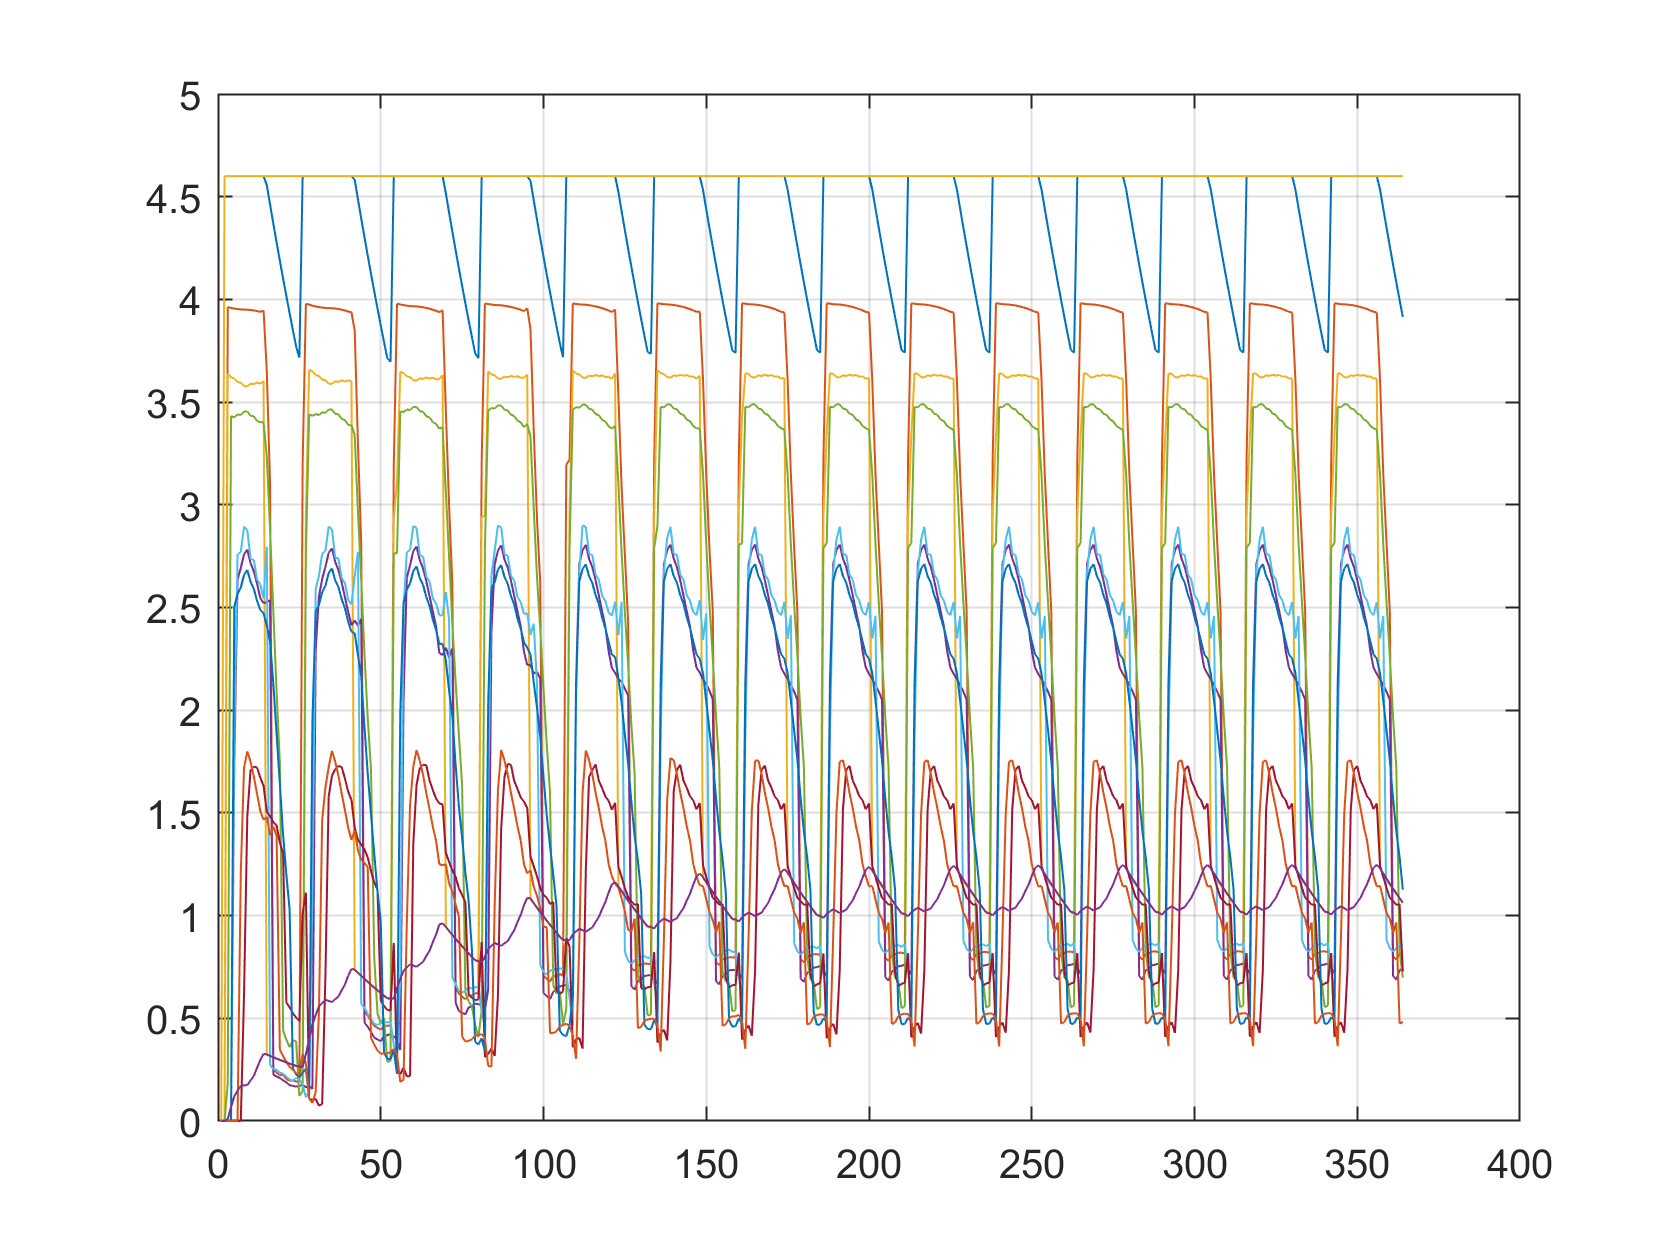


figure
plot(Q)
grid on

**Try different concentrations from 0.1 - 3.0 mg/L to find the minimum possible**

for cl2_conc = 0.1:0.1:3
    G.setNodeSourceQuality(sourceindex, cl2_conc);
    Q = G.getComputedQualityTimeSeries.NodeQuality;
    minQ = min(Q,[],2);
    minCl2 = min(minQ((end-24):end))
    if minCl2 > 0.2
        disp(['The minimum concentration is ',num2str(cl2_conc),'mg/L'])
        break
    end
end

minCl2 = 0.0076

minCl2 = 0.0160

minCl2 = 0.0246

minCl2 = 0.0318

minCl2 = 0.0390

minCl2 = 0.0480

minCl2 = 0.0560

minCl2 = 0.0647

minCl2 = 0.0700

minCl2 = 0.0810

minCl2 = 0.0861

minCl2 = 0.0951

minCl2 = 0.1046

minCl2 = 0.1110

minCl2 = 0.1190

minCl2 = 0.1261

minCl2 = 0.1371

minCl2 = 0.1418

minCl2 = 0.1509

minCl2 = 0.1621

minCl2 = 0.1680

minCl2 = 0.1761

minCl2 = 0.1822

minCl2 = 0.1921

minCl2 = 0.1987

minCl2 = 0.2064

The minimum concentration is 2.6mg/L


### **How pressure changes during fire-fighting?**

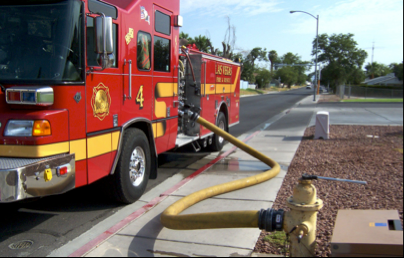

When flow is increased within the network, e.g., due to fire-fighting, the pressure changes near that location. Investigate this change, at node '32'.

G = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded sucessfuly.


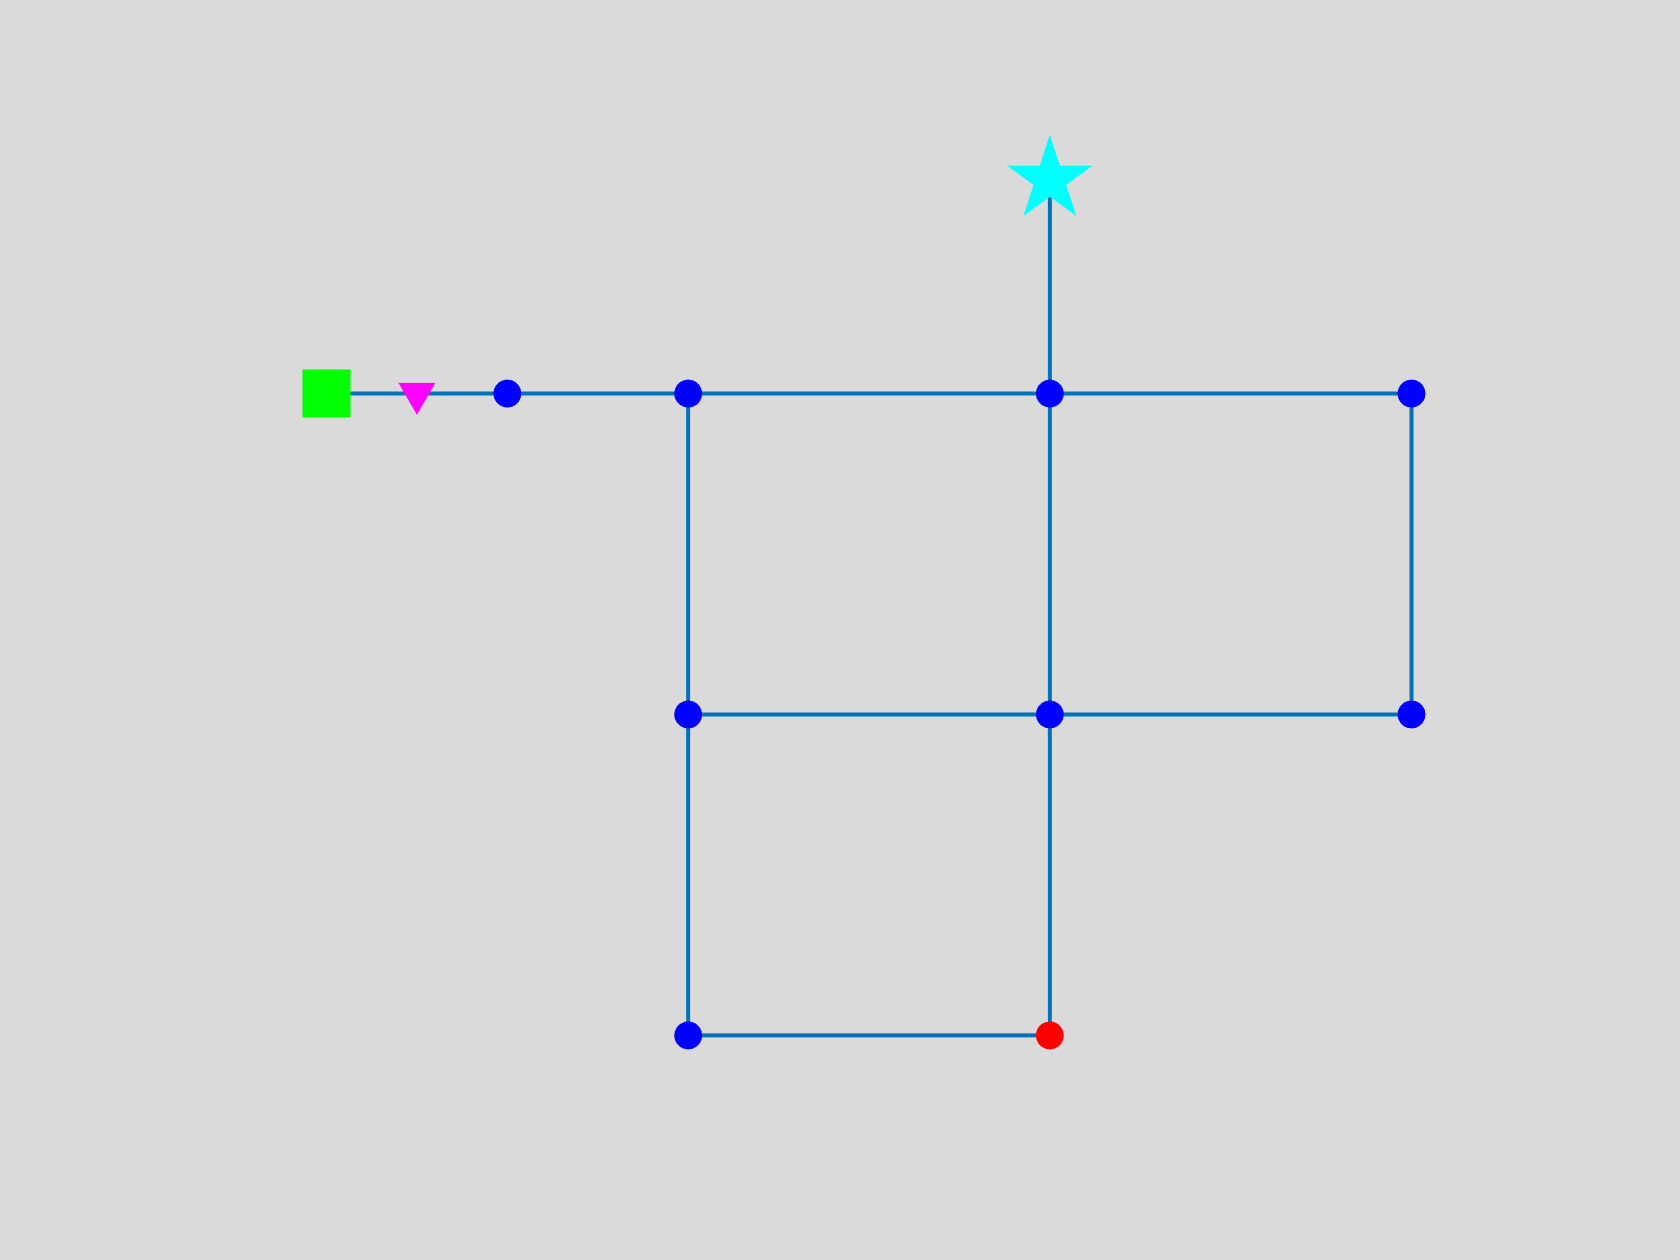

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


nodeID = {'32'};
figure
G.plot('highlightnode', nodeID)

**During fire-fighting, the base demand may increase up to x5. Will there be sufficient pressure?**

idx = G.getNodeIndex(nodeID)

idx = 9

bd = G.getNodeBaseDemands{1}(idx)

bd = 100


demand_multi = 8 % demand multiplicator

demand_multi = 8


d32 = bd *(1:demand_multi) % create the different demands

d32 =    100   200   300   400   500   600   700   800


 
p32min = zeros(1,length(d32)); % initialize variable
for i = 1:length(d32)
    G.setNodeBaseDemands(idx,d32(i));
    p32 = G.getComputedHydraulicTimeSeries.Pressure(:,idx);
    p32min(i) = min(p32);
end

**Plot demand vs pressure**

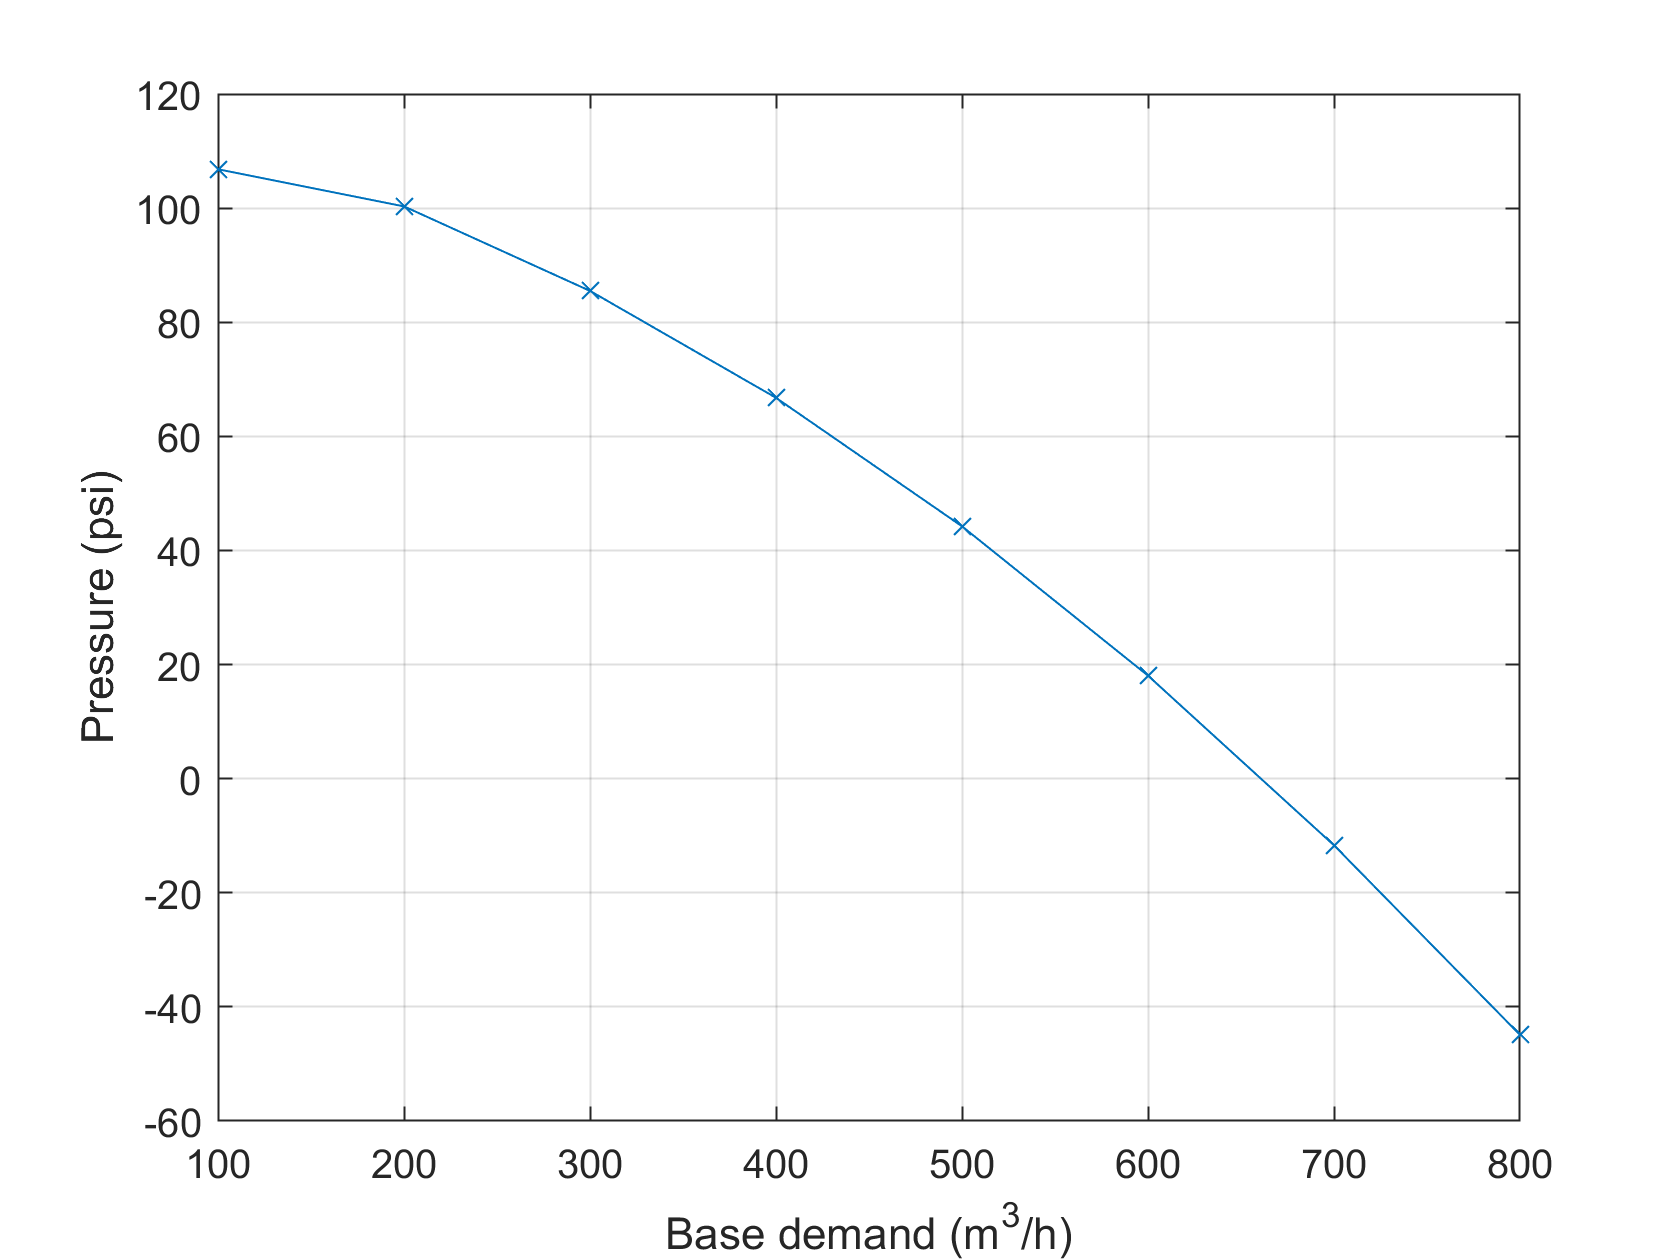

figure 
plot(d32, p32min,'x-')
grid on
xlabel('Base demand (m^3/h)')
ylabel('Pressure (psi)')

How about those negative pressures?

**Pressure Driven Simulations**

When the pressure is low, it should approximate zero. This is not the default mode of operation in EPANET. However, it's easy to set it up:

type = 'PDA';
pmin = 0;
preq = 0.1;
pexp = 0.5;
G.setDemandModel(type, pmin, preq, pexp)

Let's try this again

demand_multi = 10 % demand multiplicator

demand_multi = 10

d32 = bd *(1:demand_multi) % create the different demands

d32 =          100         200         300         400         500         600         700         800         900        1000


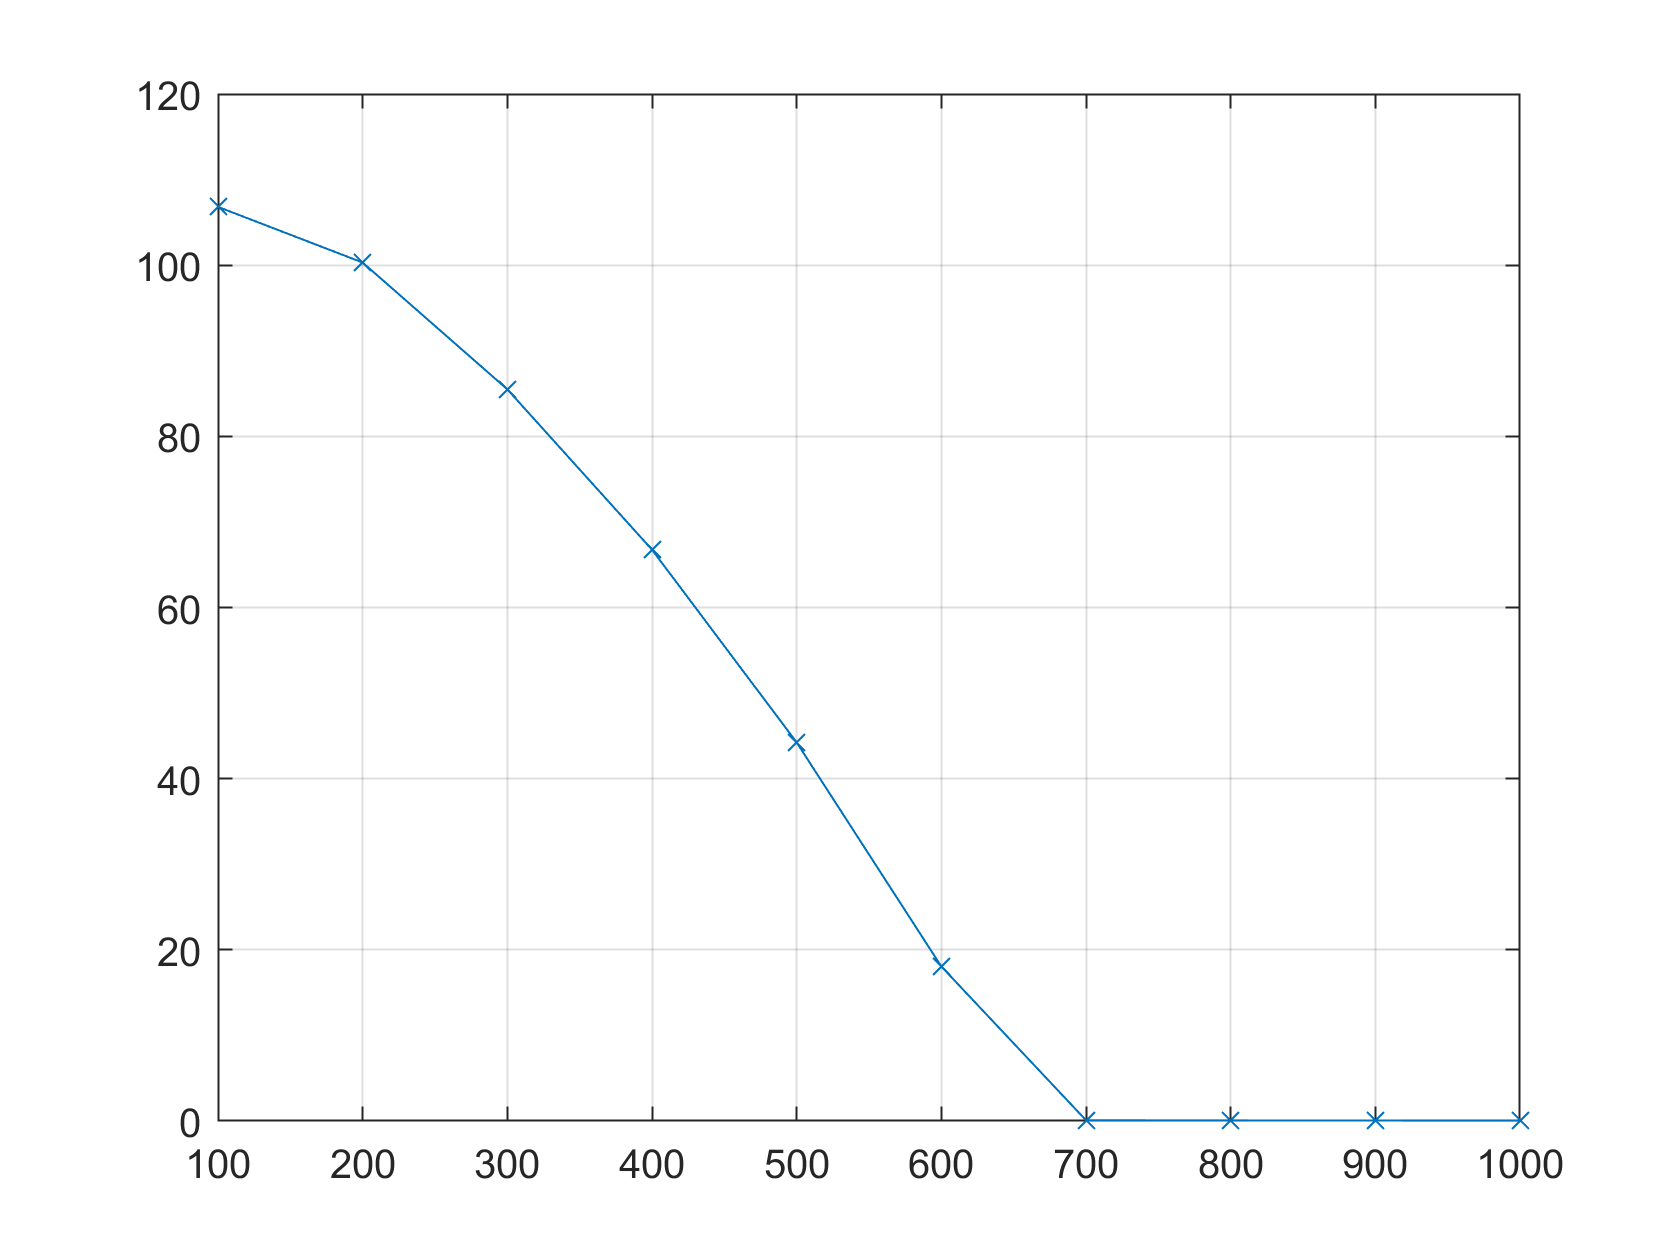


p32min = zeros(1,length(d32)); % initialize variable
for i = 1:length(d32)
    G.setNodeBaseDemands(idx,d32(i));
    p32 = G.getComputedHydraulicTimeSeries.Pressure(:,idx);
    p32min(i) = min(p32);
end

figure 
plot(d32, p32min,'x-')
grid on

### How to simulate a contamination event

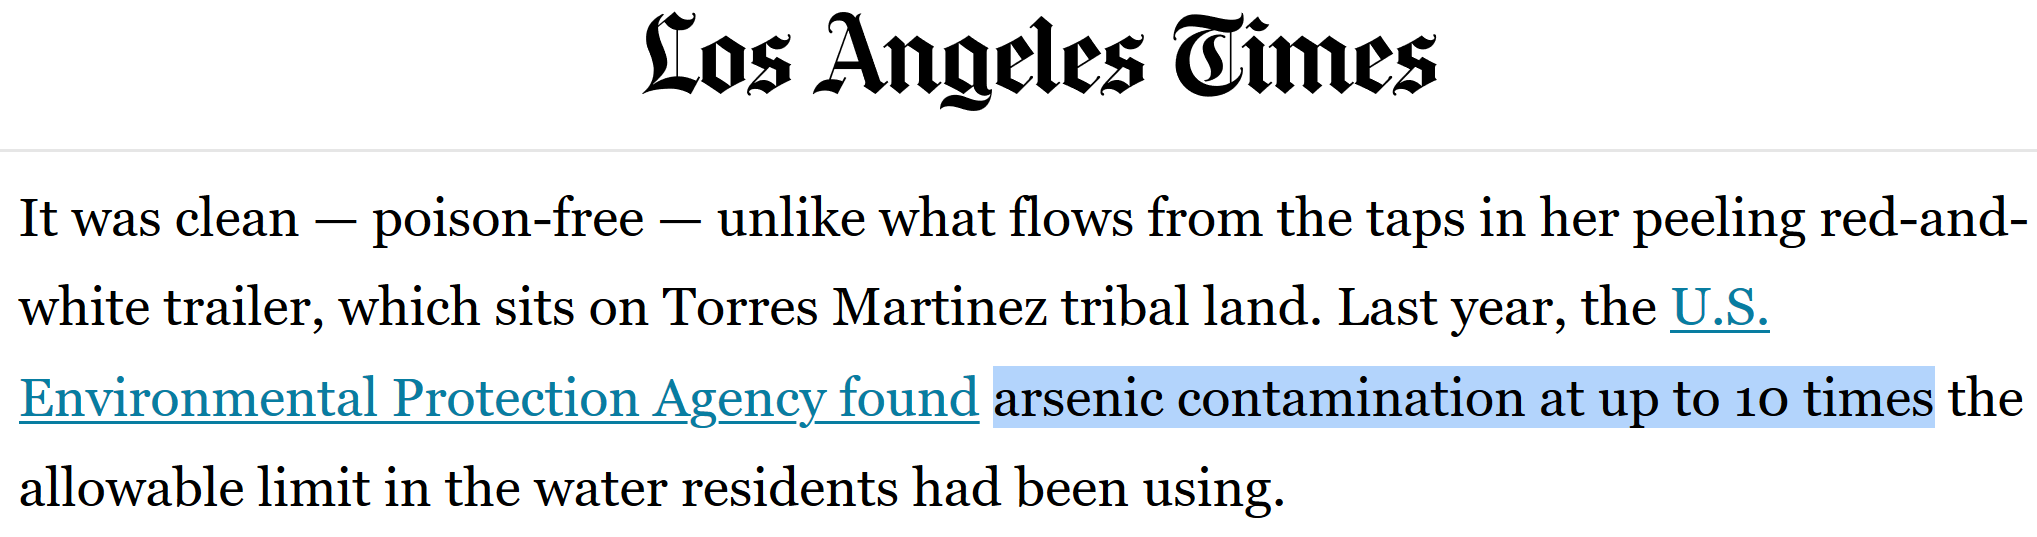

**Create an arsenite contamination event**

G = epanet('BWSN_Network_1.inp'); % Load EPANET Input file

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "BWSN_Network_1.inp"...
Input File "BWSN_Network_1.inp" loaded sucessfuly.


G.loadMSXFile('Arsenite.msx'); % Load MSX file

Prepare the simulations

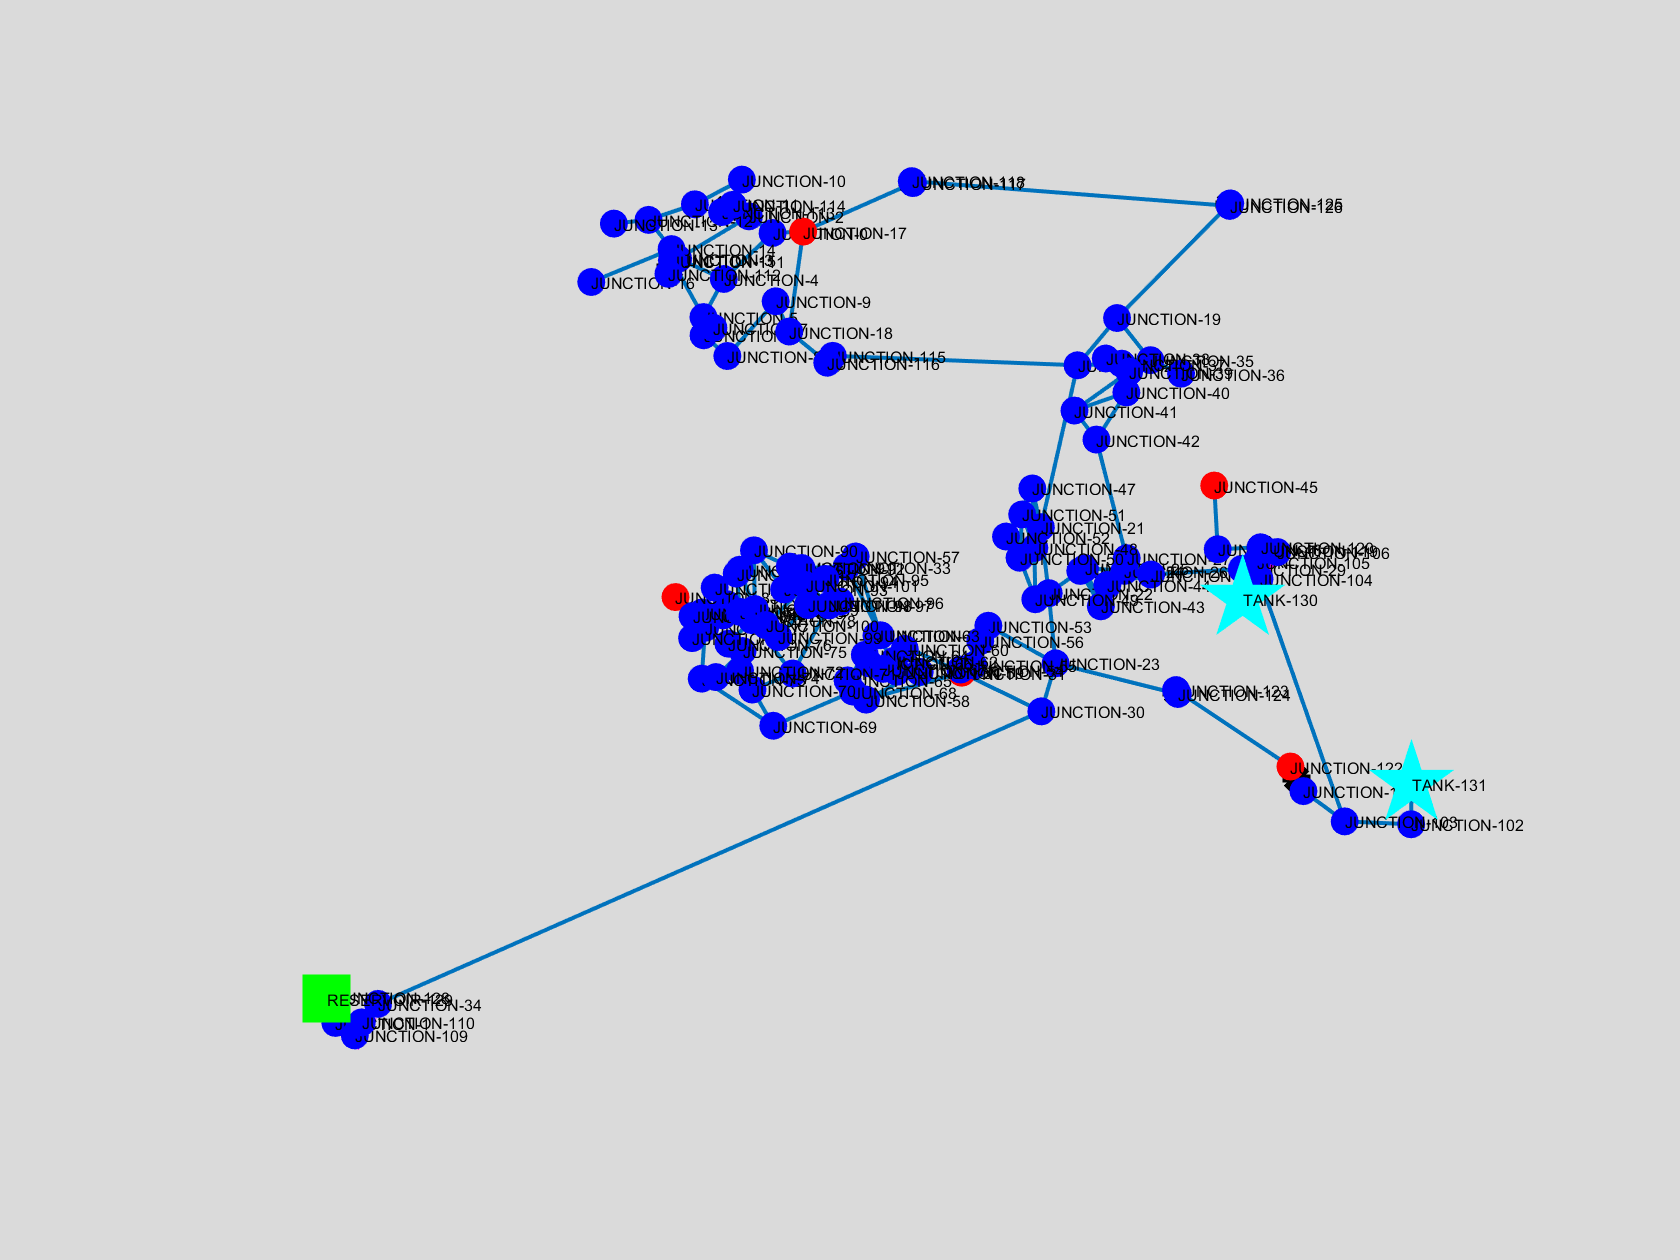

% Sensor locations
sensor_id = {'JUNCTION-17', 'JUNCTION-83', 'JUNCTION-122', 'JUNCTION-31', 'JUNCTION-45'};
sensor_index = G.getNodeIndex(sensor_id);

figure
G.plot('highlightnode', sensor_id,'nodes', 'yes', 'fontsize', 4);


% Simulation Setup
t_d = 5; % days
G.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days
G.setMSXTimeStep(3600) 

MSX unloaded


A contamination scenario needs a location (node), a contaminant concentration and a time profile (start and end time)

injection_node = {'JUNCTION-23'}

injection_node = 1×1 cell array
    {'JUNCTION-23'}


injection_conc = 0.05

injection_conc = 0.0500

injection_start_time = 150 

injection_start_time = 150

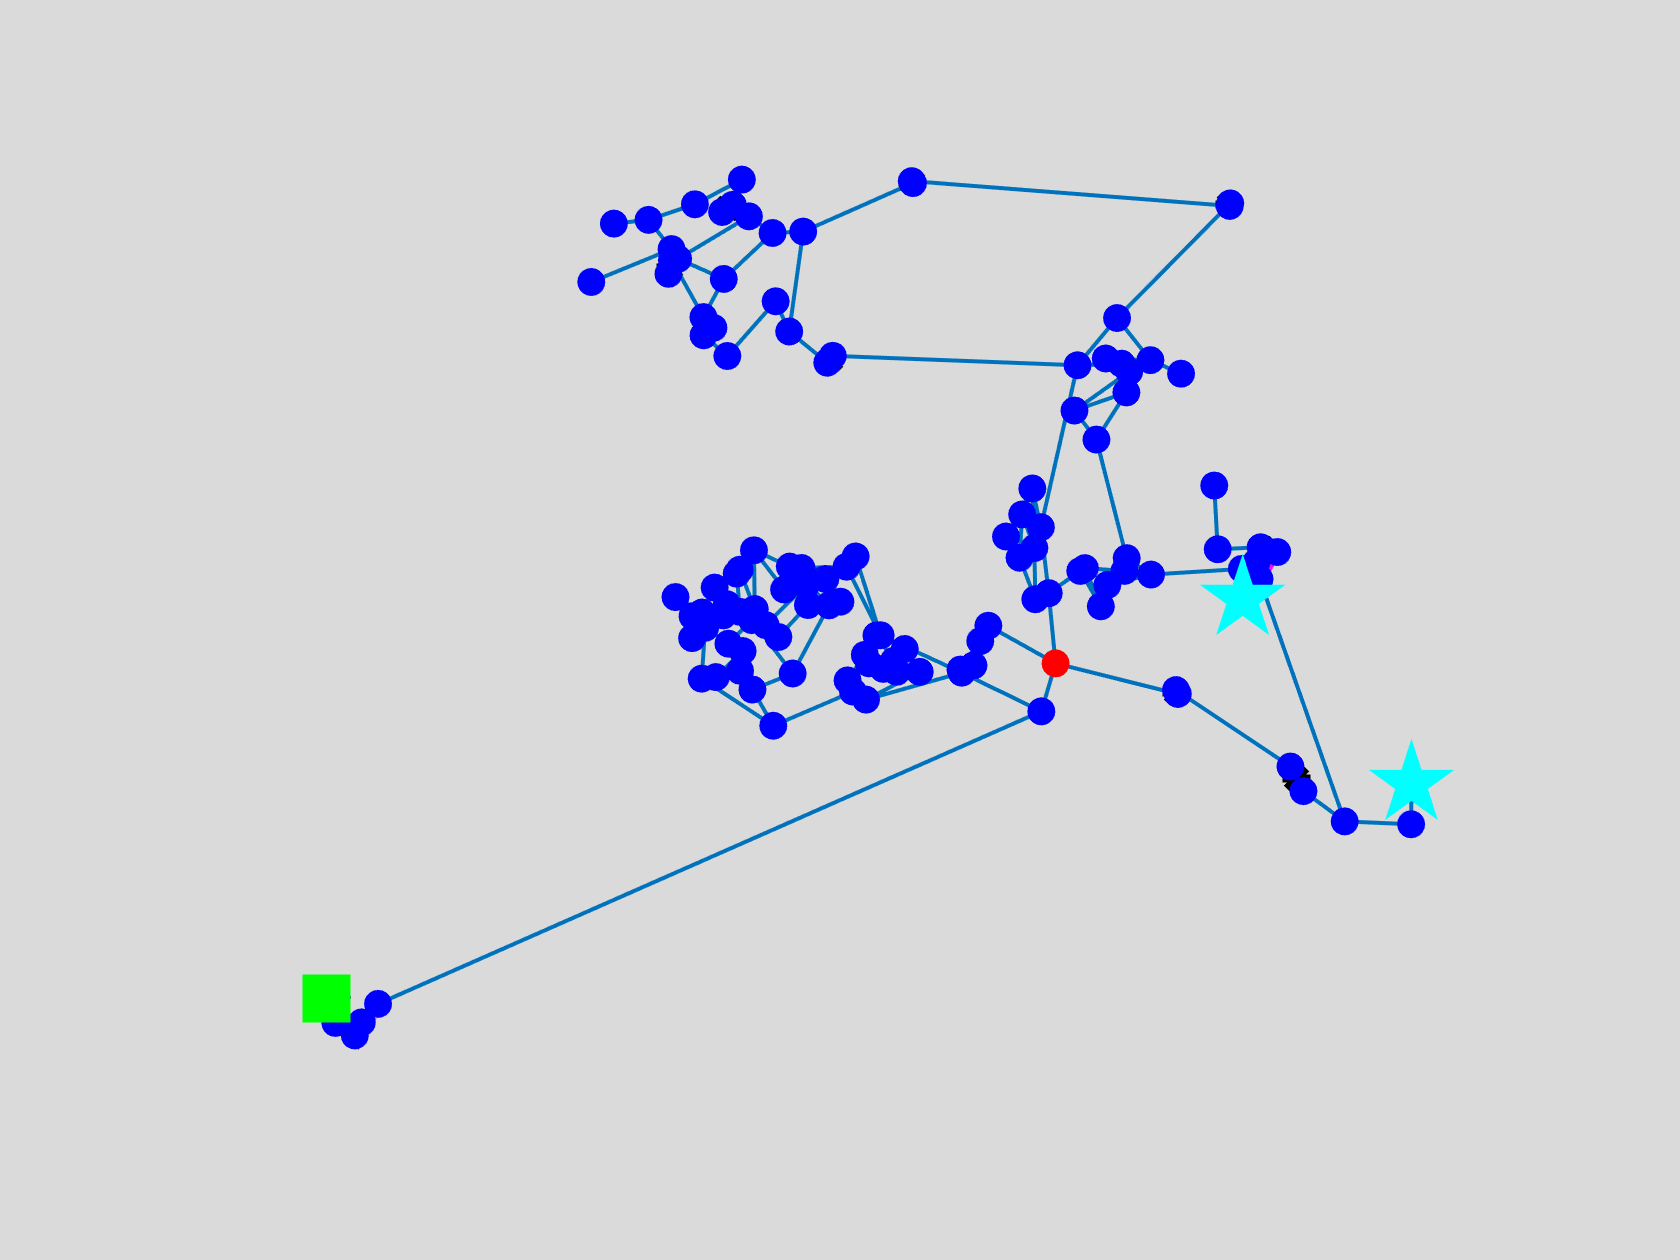

figure
G.plot('highlightnode', injection_node);

**Initialize the contamination vector (binary)**

as3_pat = zeros(1, t_d*48); % initialize the vector
as3_pat(injection_start_time:end) = 1; % create the injection pattern 

**Simulate the contamination of water with arsenite**

% Specify Arsenite injection source
G.setMSXSources(injection_node, 'AsIII', 'Setpoint', injection_conc, 'AS3PAT'); 
% Set pattern for injection
G.setMSXPattern('AS3PAT',as3_pat);
% Solve hydraulics and MSX quality dynamics
Qmsx = G.getMSXComputedQualityNode(sensor_index); 

**Plot the results**

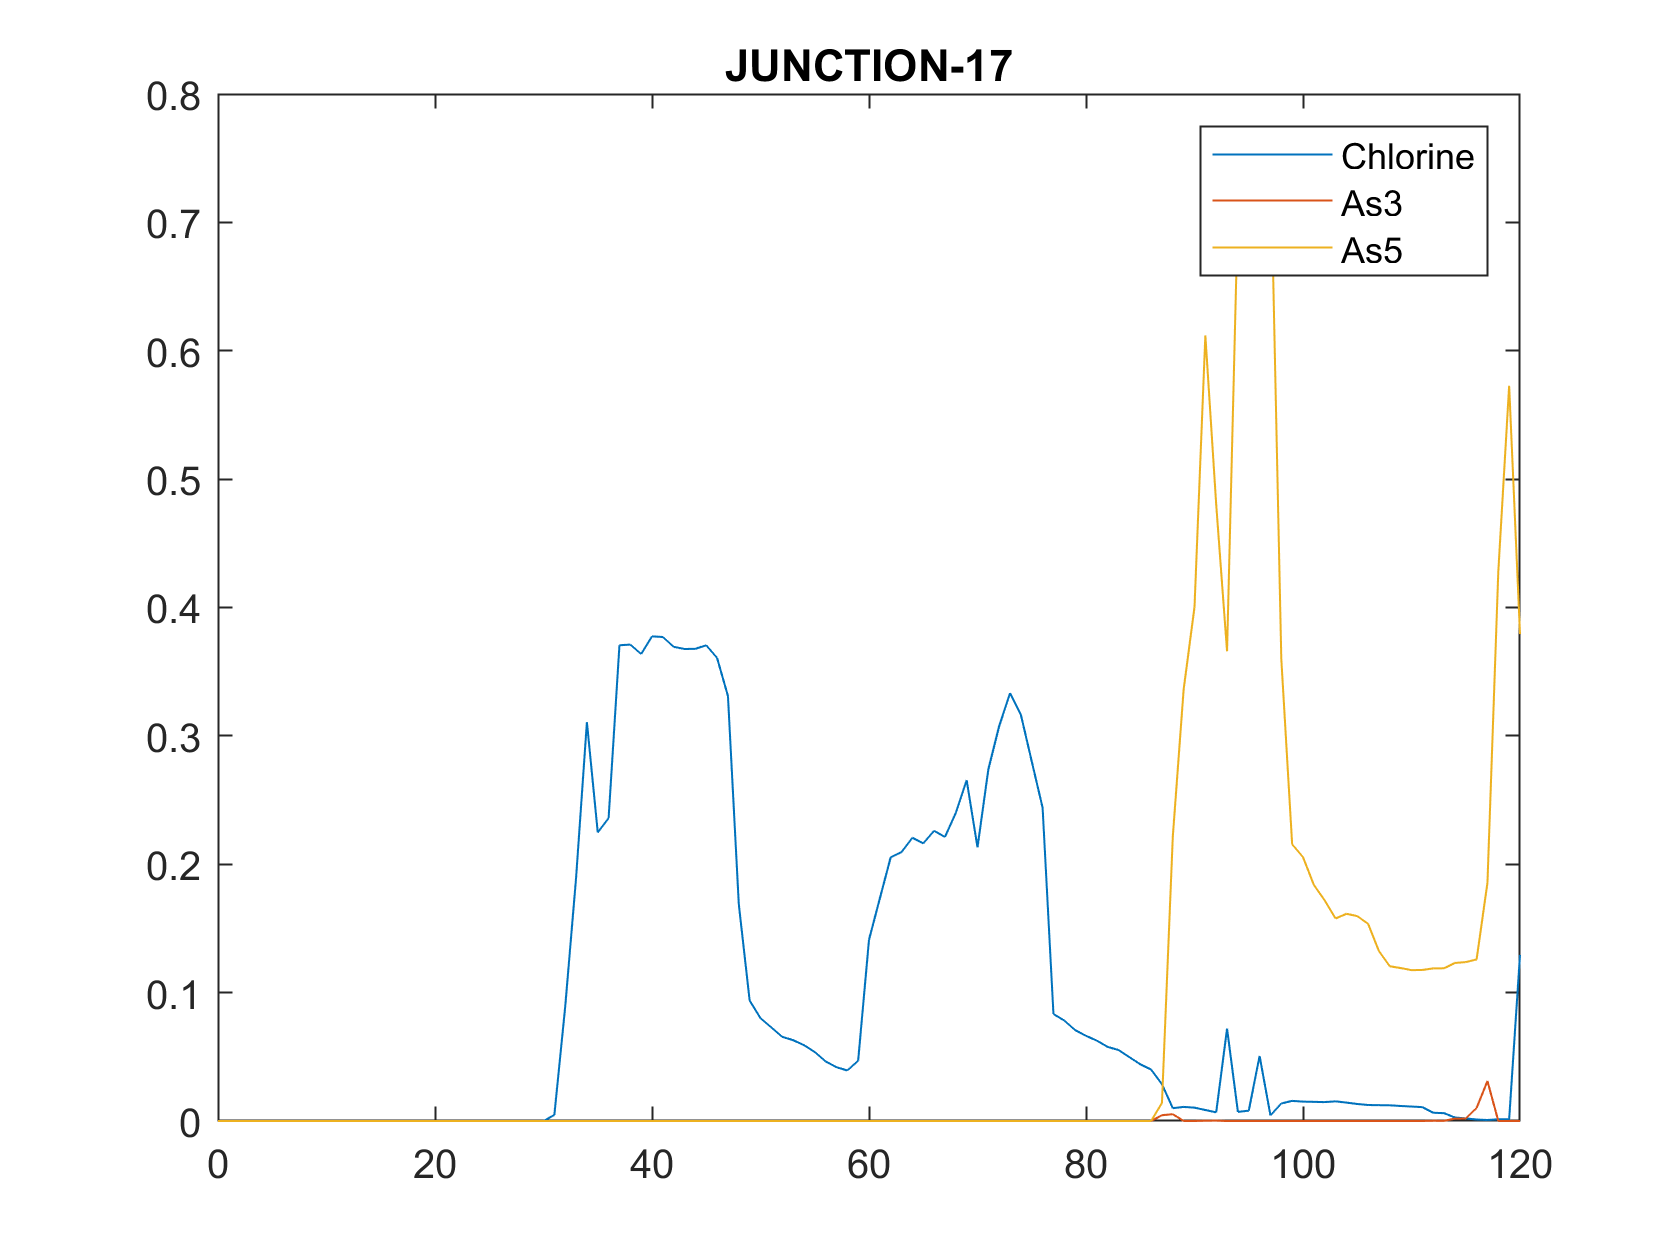

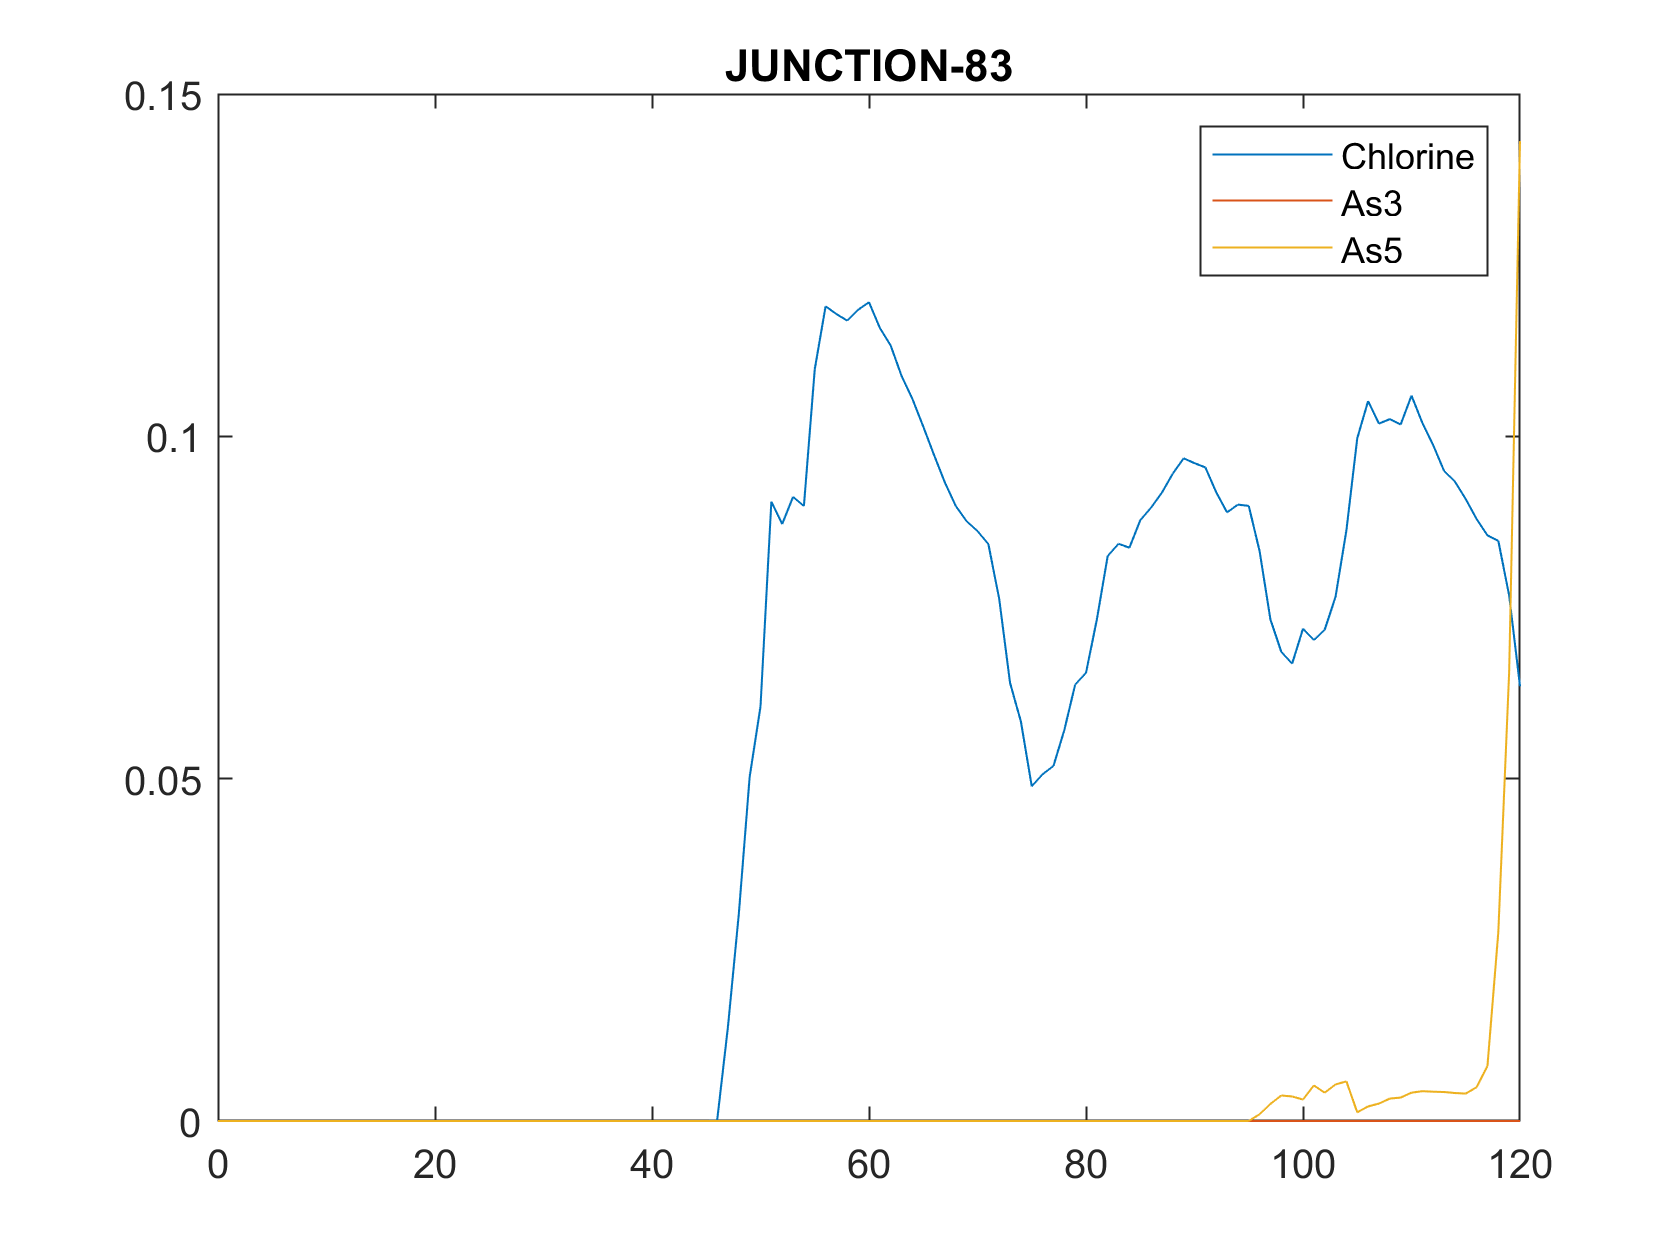

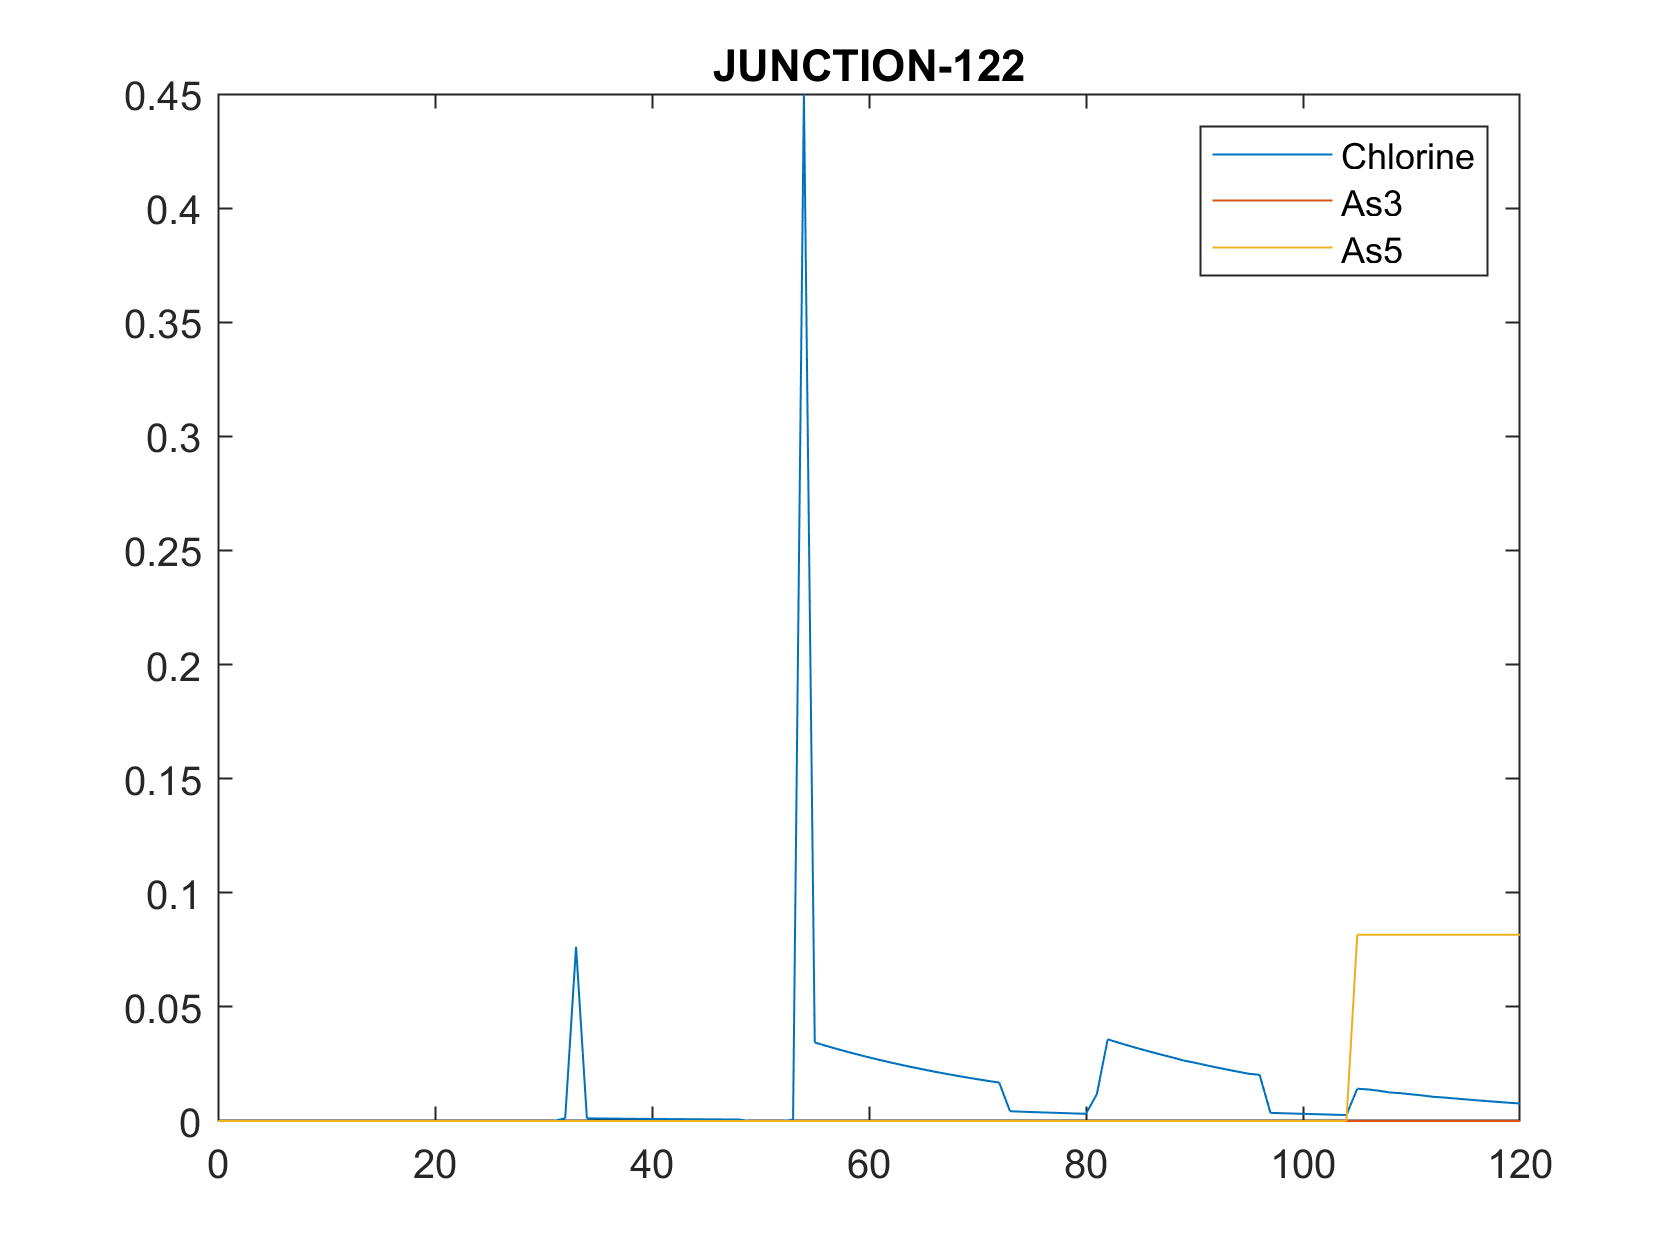

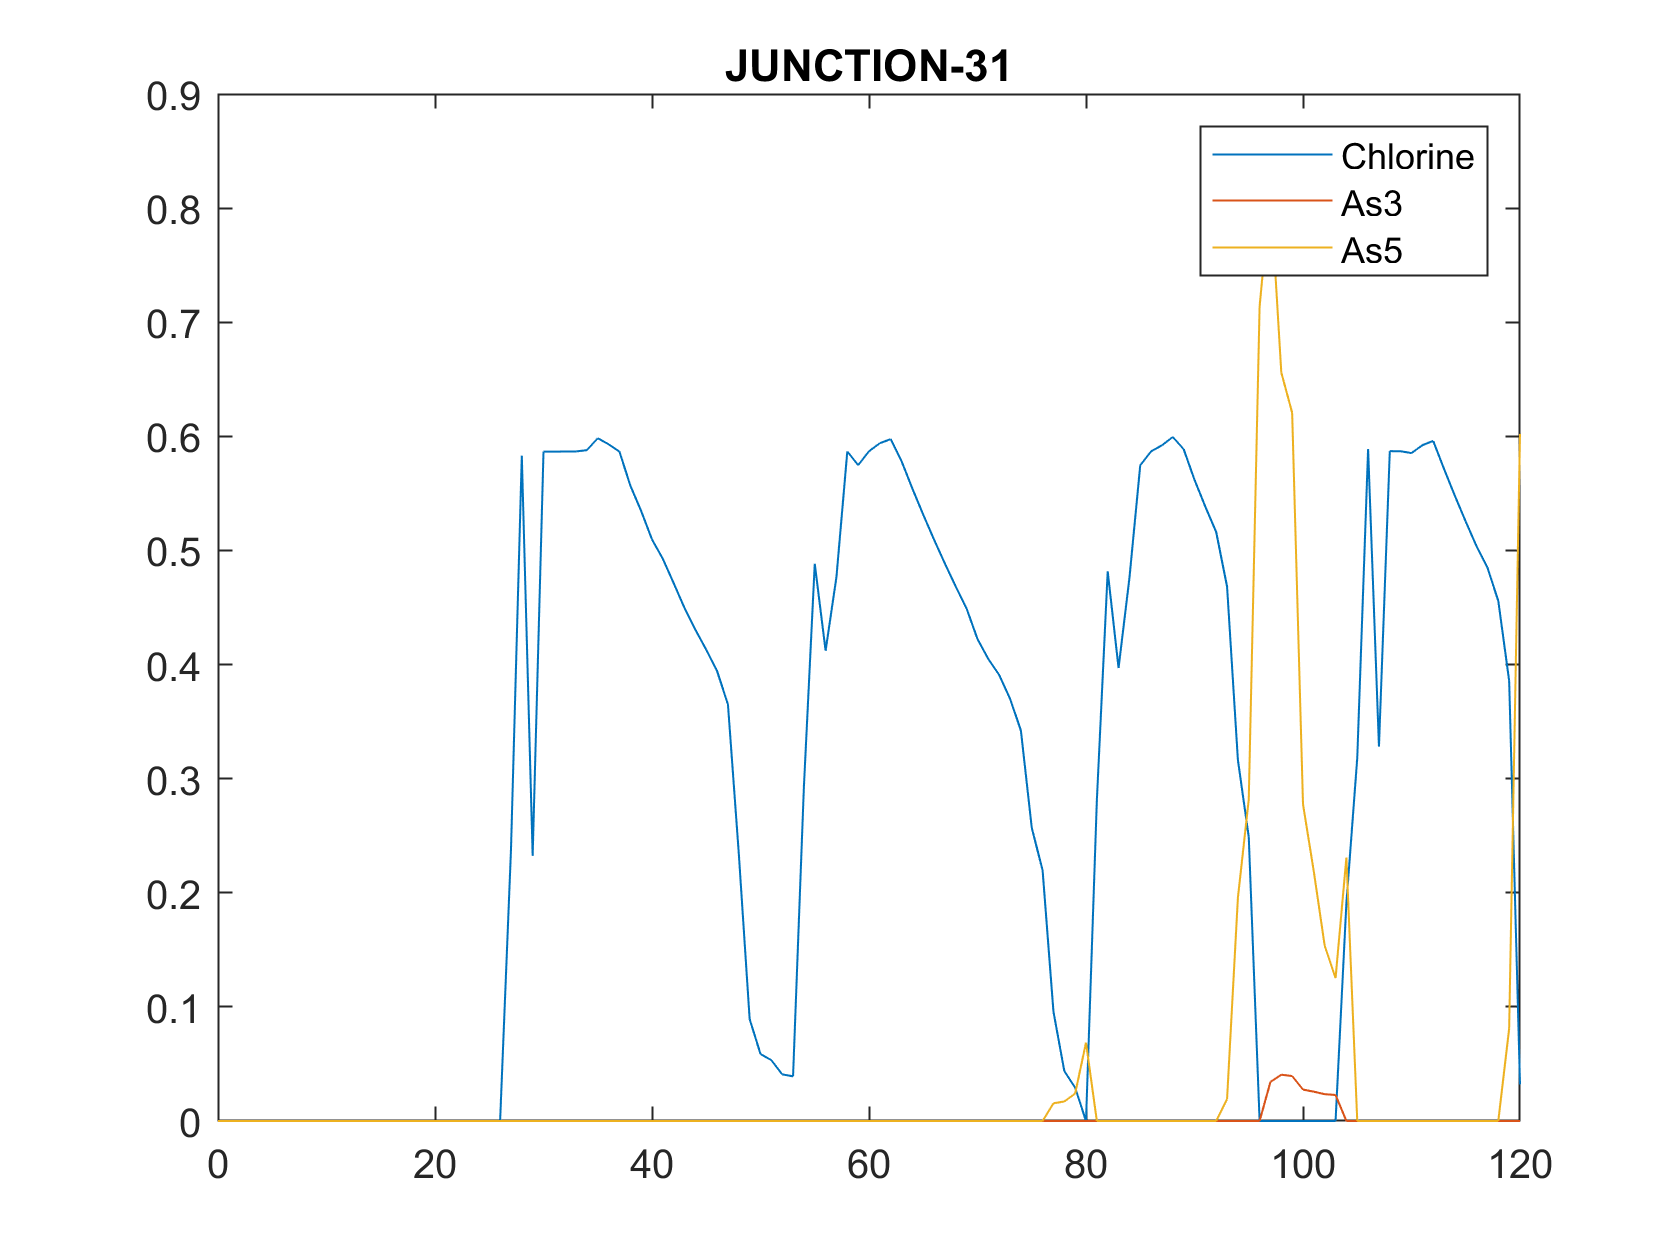

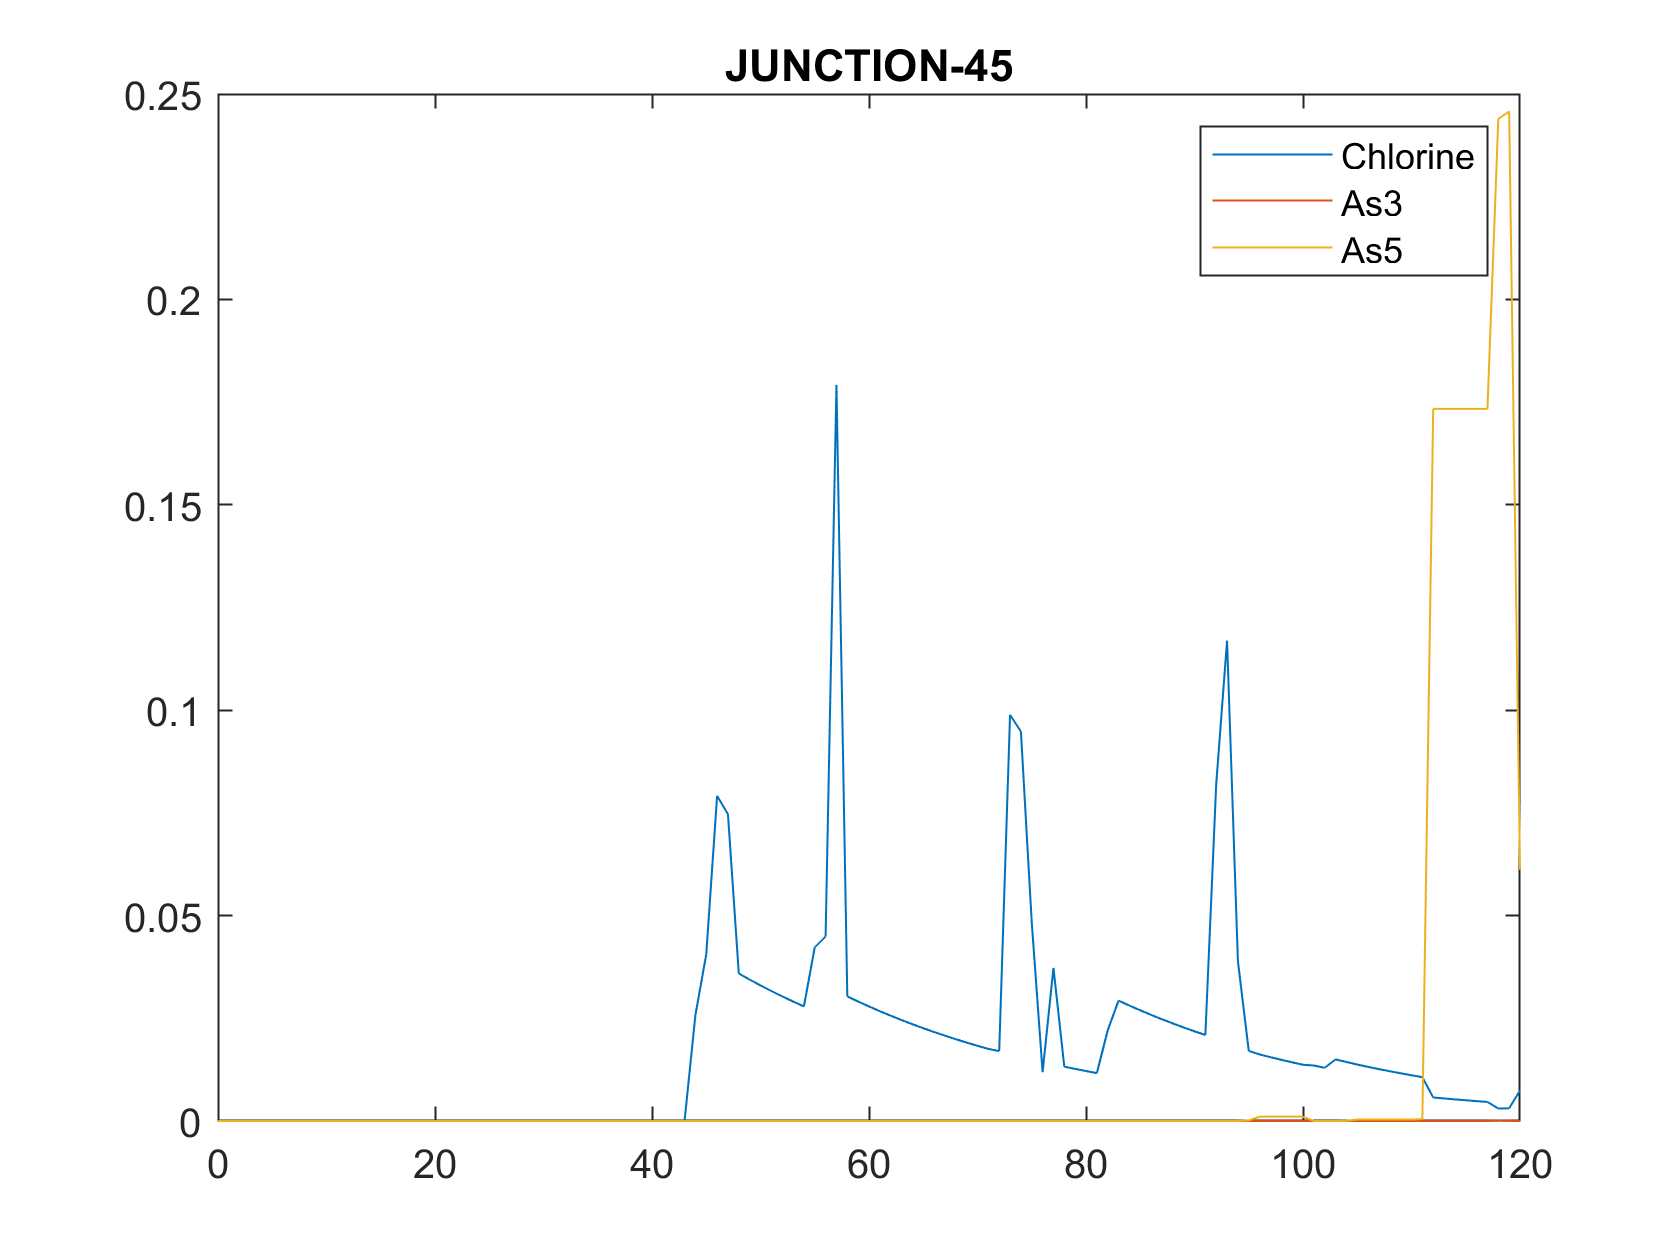

for i = 1:5
    figure
    plot(Qmsx.Time/3600, Qmsx.Quality{i})
    legend('Chlorine','As3', 'As5')
    title(sensor_id(i))
end

### **Monte Carlo simulations for contamination detection**

**Initialize the simulation**

rng(1)

%% Load EPANET Network and MSX
G = epanet('BWSN_Network_1.inp'); % Load EPANET Input file

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "BWSN_Network_1.inp"...
Input File "BWSN_Network_1.inp" loaded sucessfuly.


G.loadMSXFile('Arsenite.msx'); % Load MSX file

% Sensor locations
sensor_id = {'JUNCTION-17', 'JUNCTION-83', 'JUNCTION-122', 'JUNCTION-31', 'JUNCTION-45'}

sensor_id = 1×5 cell array
    {'JUNCTION-17'}    {'JUNCTION-83'}    {'JUNCTION-122'}    {'JUNCTION-31'}    {'JUNCTION-45'}


sensor_index = G.getNodeIndex(sensor_id);

%% Simulation Setup
t_d = 5 % days

t_d = 5

G.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days

%% Get Network data
demand_pattern = G.getPattern;
roughness_coeff = G.getLinkRoughnessCoeff;
node_id = G.getNodeNameID;

G.setMSXTimeStep(3600)

MSX unloaded


**Setup uncertainties**

%% Scenarios
Ns = 20; % Number of scenarios to simulate
u_p = 0.20 % pattern uncertainty

u_p = 0.2000

u_r = 0.20 % roughness coefficient uncertainty

u_r = 0.2000

**Create the scenarios - first without contamination, to compute the bounds**

max_inj_conc = 0.0

max_inj_conc = 0

inj_start_time = 2*48 % after day 2 (Dt = 30min)

inj_start_time = 96

inj_duration = 24 % maximum duration of 12 hours

inj_duration = 24

% Injection location, magnitude, start time, duration 
inj_sc=[randi(G.NodeCount,Ns,1), max_inj_conc*rand(Ns,1), randi(48,Ns,1)+inj_start_time, randi(inj_duration,Ns,1)] 

inj_sc =     54     0   144     3
    93     0   132    10
     1     0   110    17
    40     0   134    10
    19     0   101     2
    12     0   118    13
    25     0   140    16
    45     0   111    13
    52     0   110    23
    70     0   103    15


**Run epochs**

for i = 1:Ns
    disp(['Iteration ', int2str(i)])
    
    % Randomize demands
    r_p = -u_p + 2*u_p.*rand(size(demand_pattern,1),size(demand_pattern,2));
    new_demand_pattern = demand_pattern + demand_pattern.*r_p;
    G.setPatternMatrix(new_demand_pattern); % Set new patterns
    
    % Randomize pipe roughness
    r_r = -u_r + 2*u_r.*rand(size(roughness_coeff,1),size(roughness_coeff,2));
    new_roughness_coeff = roughness_coeff + roughness_coeff.*r_r;
    G.setLinkRoughnessCoeff(new_roughness_coeff); % Set new roughness coefficients
    
    % Randomize injection
    %G.setMSXSources(node_id(inj_sc(i,1)), 'AsIII', 'Setpoint', inj_sc(i,2), 'AS3PAT'); % Specify Arsenite injection source
    %as3_pat = zeros(1, t_d*48);
    %as3_pat(inj_sc(i,3):(inj_sc(i,3)+inj_sc(i,4))) = 1; % 
    %G.setMSXPattern('AS3PAT',as3_pat); % Set pattern for injection
    QQ{i} = G.getMSXComputedQualityNode(sensor_index); % Solve hydraulics and MSX quality dynamics
    %G.setMSXSources(node_id(inj_sc(i,1)), 'AsIII', 'Setpoint', 0, 'AS3PAT'); % Reset injection source
end

Iteration 1
Iteration 2
Iteration 3
Iteration 4
Iteration 5
Iteration 6
Iteration 7
Iteration 8
Iteration 9
Iteration 10
Iteration 11
Iteration 12
Iteration 13
Iteration 14
Iteration 15
Iteration 16
Iteration 17
Iteration 18
Iteration 19
Iteration 20


**Plot the results without contaminations**

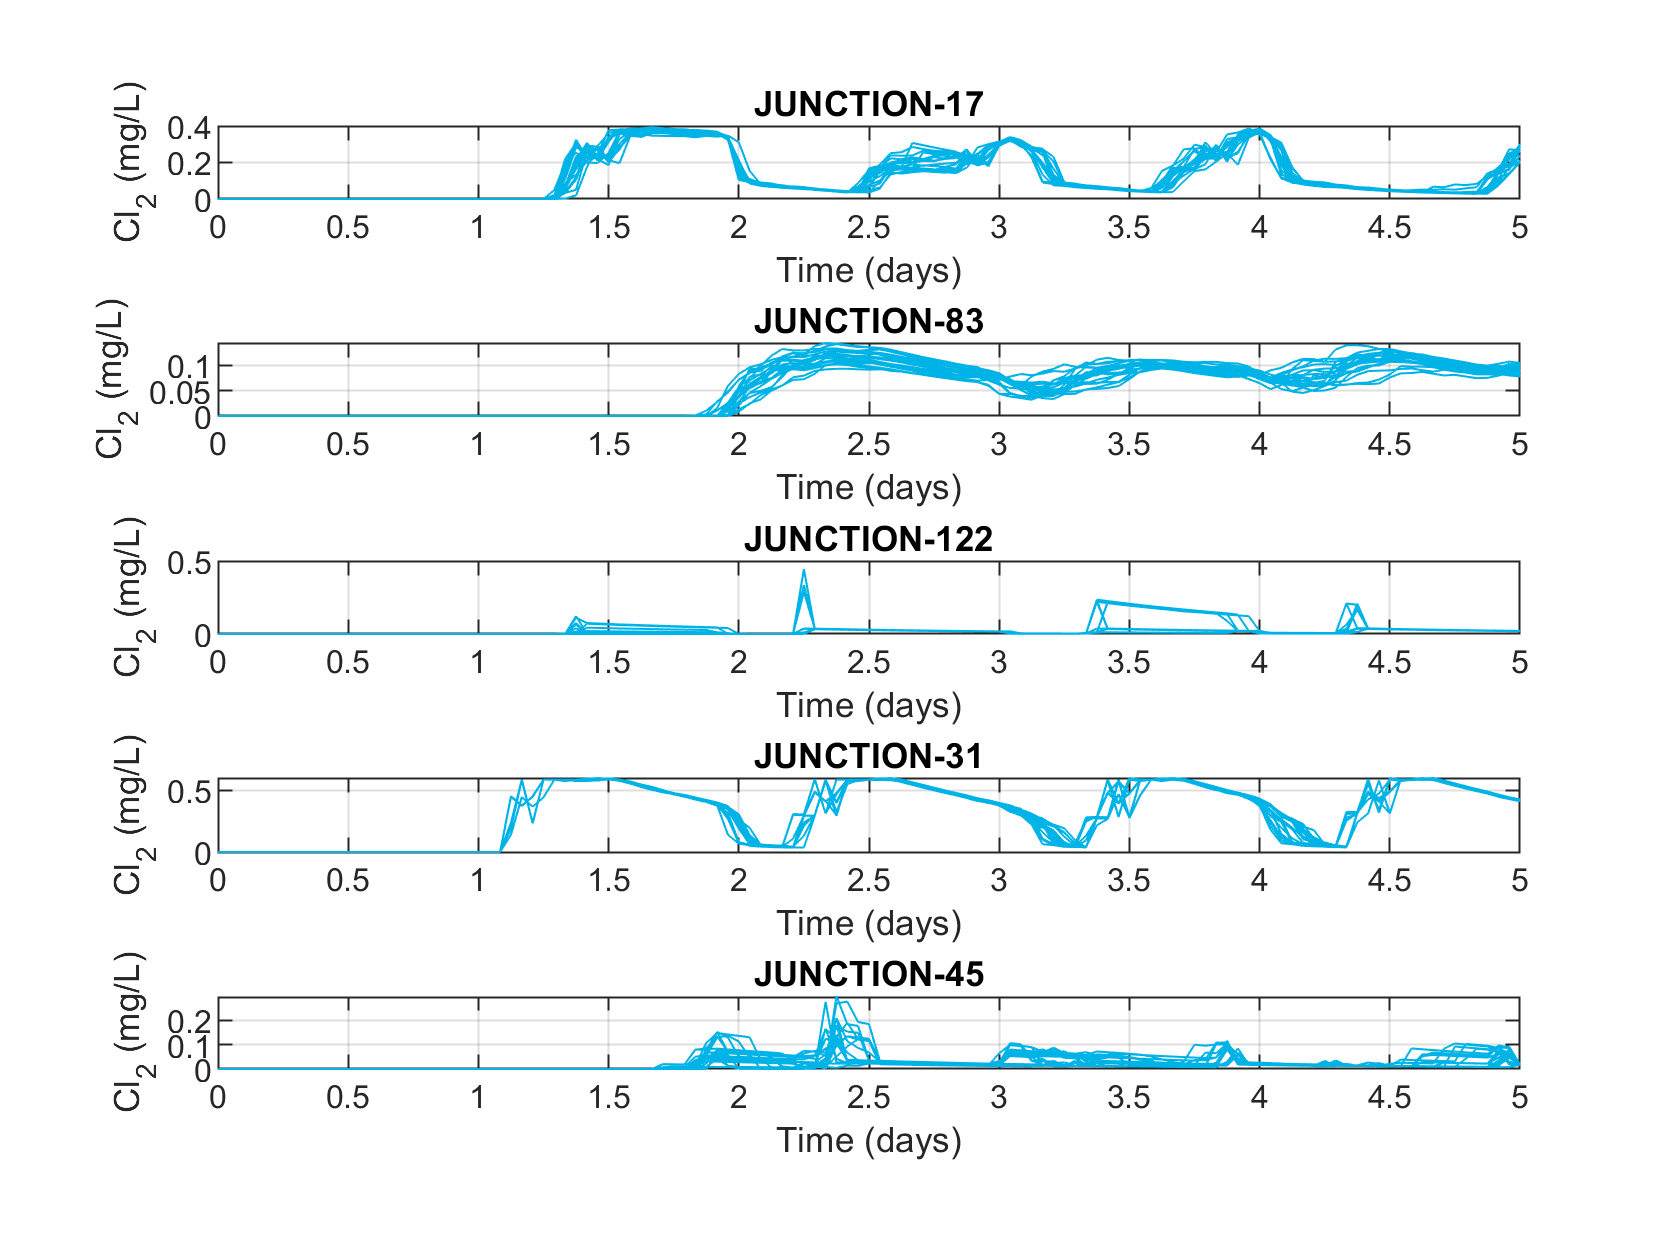

figure
for i = 1:Ns
    for j = 1:length(sensor_index)
       subplot(5,1,j)
       plot(QQ{i}.Time/24/60/60, QQ{i}.Quality{j}(:,1),'-','Color',[0,0.7,0.9]); hold on; grid on
       Qtable{j}(:,i) = QQ{i}.Quality{j}(:,1);
    end
end
for i = 1:length(sensor_index)
   subplot(5,1,i)
   title(sensor_id{i})
   ylabel('Cl_2 (mg/L)')
   xlabel('Time (days)')
end

**Compute the intervals for each sensor**

for j = 1:length(sensor_index)
    % Upper Bound
    UBQ(:,j) = max(Qtable{j},[],2); 
    % Lower Bound    
    LBQ(:,j) = min(Qtable{j},[],2);
end

**Plot the intervals**

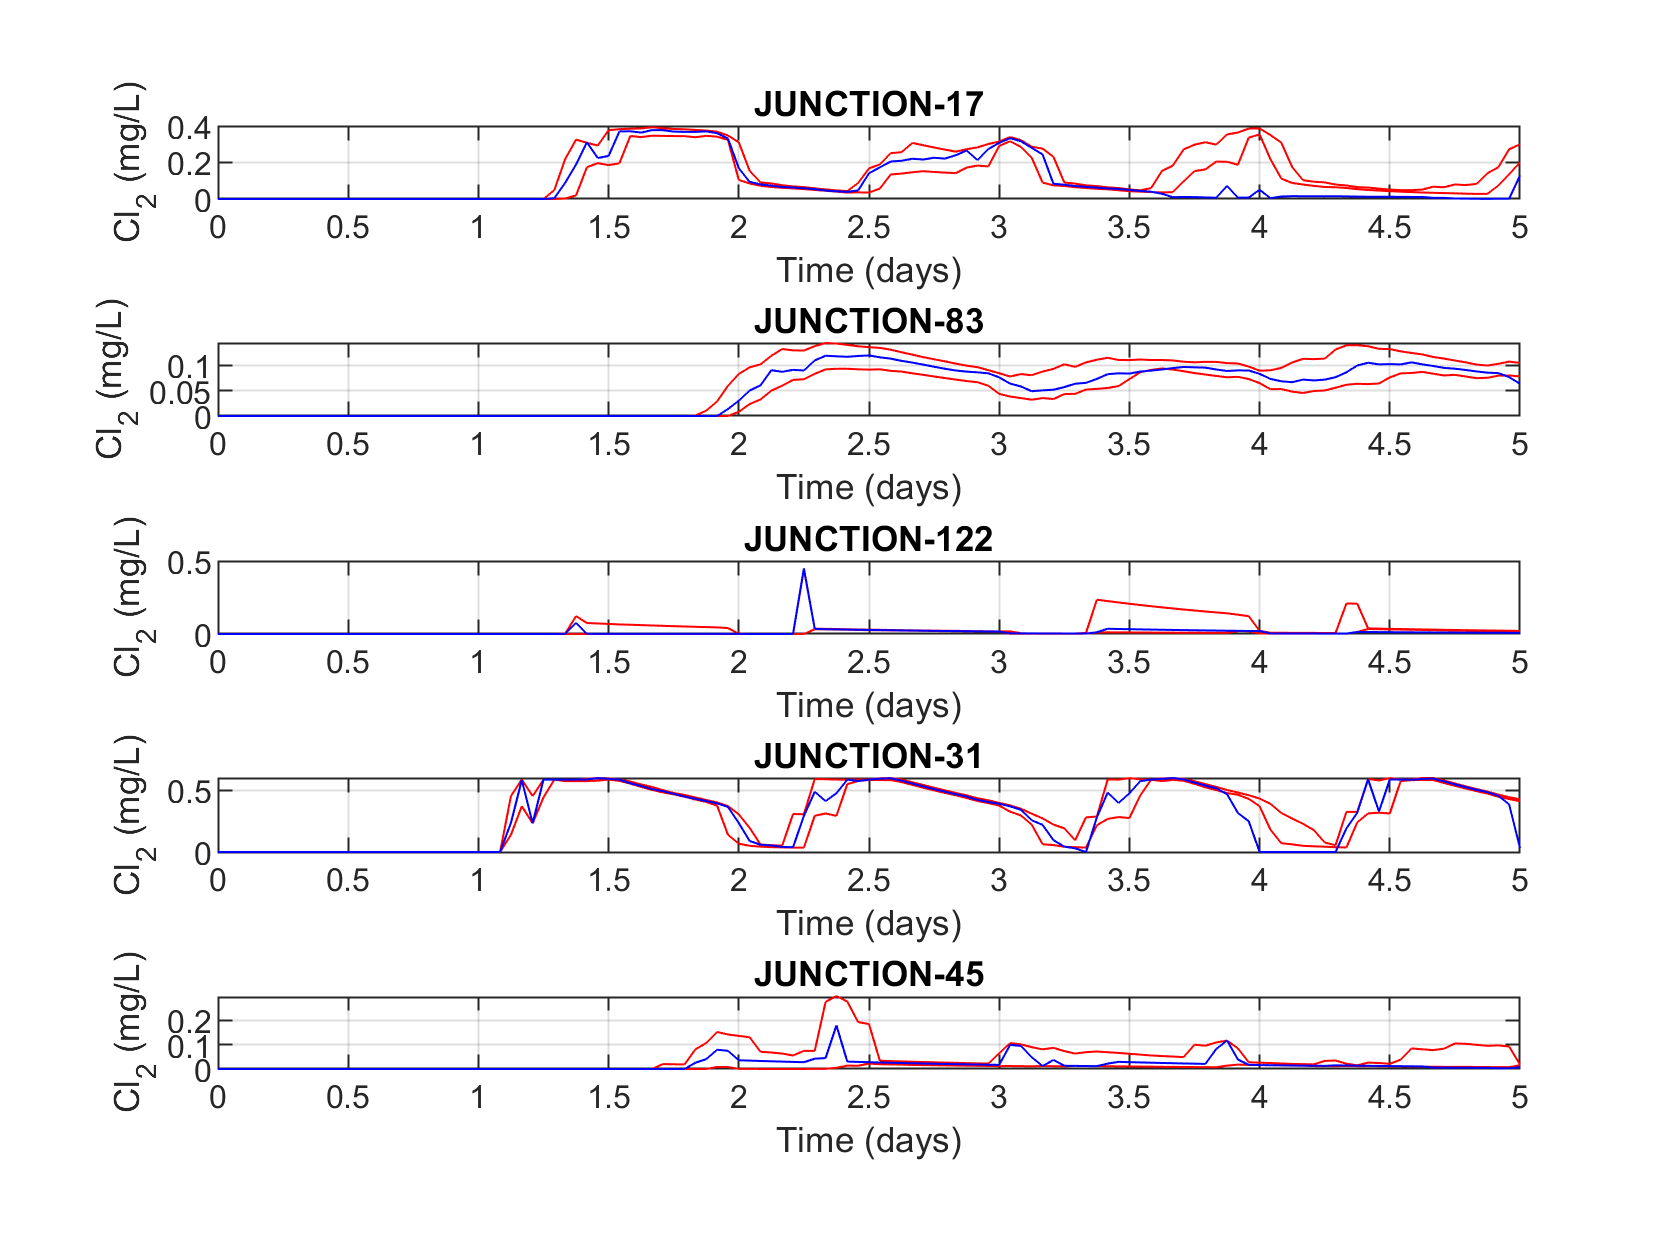

figure
for j = 1:length(sensor_index)
       subplot(5,1,j)
       plot(QQ{i}.Time/24/60/60, UBQ(:,j),'r-'); 
       hold on; 
       plot(QQ{i}.Time/24/60/60, LBQ(:,j),'r-');

       % plot the contamination event simulated earier
       plot(Qmsx.Time/24/60/60, Qmsx.Quality{j}(:,1), 'b-')
       grid on
end
for i = 1:length(sensor_index)
   subplot(5,1,i)
   title(sensor_id{i})
   ylabel('Cl_2 (mg/L)')
   xlabel('Time (days)')
end

### **Contamination detection**

Compare what the model predicts, with what the (chlorine) sensors measure. If the difference is significantly larger, then put a fault warning.


$$e = y - \hat{y}$$


if $e > \bar{\epsilon}$ then fault flag $\phi(k) = 1$

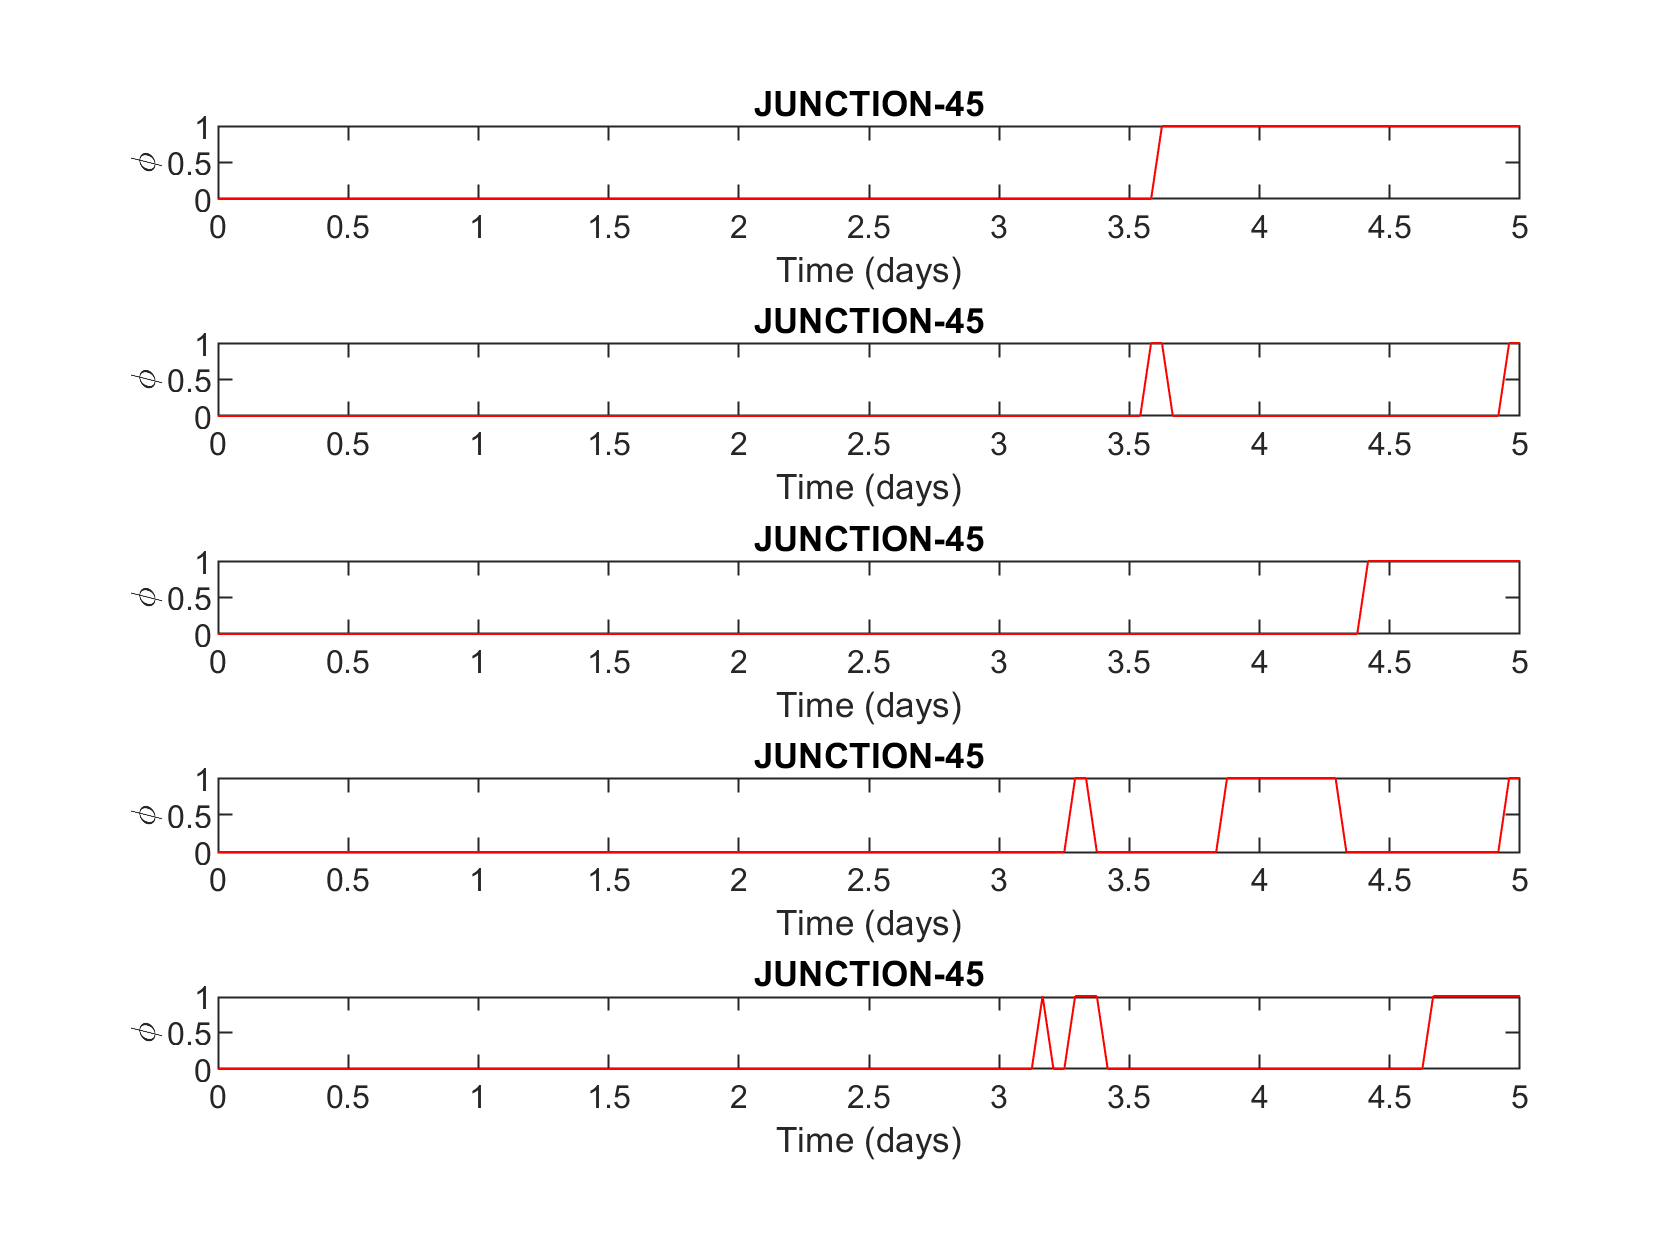

figure
for j = 1:length(sensor_index)   
    % difference between the lower bound and the measured value
    e = LBQ(:,j) - Qmsx.Quality{j}(:,1);
    % create the \phi signal by putting 1 when the error is > 0
    phi = e>0;

    % plot the results
    subplot(5,1,j)
    plot(Qmsx.Time/24/60/60, phi, 'r-')
    title(sensor_id{i})
    ylabel('\phi')
    xlabel('Time (days)')
end

### **Sensor placement for quality monitoring**

Large-scale networks are difficult to monitor, and it is not possible to have sensors everywhere in the system, mainly due to costs. For this reason, we need to select the best locations to install sensors, in order to guarantee certain criteria, such as:

- Network coverage

- Detection delay

- Impact (e.g., number of people affected)

Sensor placement requires the following steps:

- Create simulation scenarios of contamination events

- Execute the simulation scenarios

- Measure the impact

- Formulate and solve an optimization problem

- If multiple objectives, costruct the Pareto front and select one solution

rng(1)

%% Load EPANET Network and MSX
G = epanet('BWSN_Network_1.inp'); % Load EPANET Input file

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "BWSN_Network_1.inp"...
Input File "BWSN_Network_1.inp" loaded sucessfuly.



%% Simulation Setup
t_d = 5 % days

t_d = 5

G.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days

%% Get Network data
demand_pattern = G.getPattern;
roughness_coeff = G.getLinkRoughnessCoeff;
node_id = G.getNodeNameID;
Nnodes = G.getNodeCount;

**Setup uncertainties**

%% Scenarios
Ns = 50; % Number of scenarios to simulate
u_p = 0.2 % pattern uncertainty

u_p = 0.2000

u_r = 0.2 % roughness coefficient uncertainty

u_r = 0.2000

**Create the scenarios - first without contamination, to compute the bounds**

max_inj_conc = 10.0

max_inj_conc = 10

inj_start_time = 1 % after day 2 (Dt = 30min)

inj_start_time = 1

inj_duration = 24 % maximum duration of 12 hours

inj_duration = 24

% Injection location, magnitude, start time, duration 
inj_sc=[randi(G.NodeCount,Ns,1), max_inj_conc*ones(Ns,1), (inj_start_time)*ones(Ns,1), inj_duration*ones(Ns,1)] 

inj_sc =     54    10     1    24
    93    10     1    24
     1    10     1    24
    40    10     1    24
    19    10     1    24
    12    10     1    24
    25    10     1    24
    45    10     1    24
    52    10     1    24
    70    10     1    24


**Create the coverage matrix**

The coverage matrix is a binary matrix, where earh row is a scenario, and each column is a node. If a certain contamination scenario affects (can reach) a certain node, the flag is true, else false.

K = zeros(1,Nnodes);
for i = 1:Ns
    disp(['Iteration ', int2str(i)])
    
    % Randomize demands
    r_p = -u_p + 2*u_p.*rand(size(demand_pattern,1),size(demand_pattern,2));
    new_demand_pattern = demand_pattern + demand_pattern.*r_p;
    G.setPatternMatrix(new_demand_pattern); % Set new patterns
    
    % Randomize pipe roughness
    r_r = -u_r + 2*u_r.*rand(size(roughness_coeff,1),size(roughness_coeff,2));
    new_roughness_coeff = roughness_coeff + roughness_coeff.*r_r;
    G.setLinkRoughnessCoeff(new_roughness_coeff); % Set new roughness coefficients
    
    c = zeros(1,Nnodes);
    c(inj_sc(i,1)) = inj_sc(i,2);
    G.setNodeInitialQuality(c);
    
    qsp = G.getComputedTimeSeries.NodeQuality;
    K(i,:) = max(qsp)>0;
end

Iteration 1
Iteration 2
Iteration 3
Iteration 4
Iteration 5
Iteration 6
Iteration 7
Iteration 8
Iteration 9
Iteration 10
Iteration 11
Iteration 12
Iteration 13
Iteration 14
Iteration 15
Iteration 16
Iteration 17
Iteration 18
Iteration 19
Iteration 20
Iteration 21
Iteration 22
Iteration 23
Iteration 24
Iteration 25
Iteration 26
Iteration 27
Iteration 28
Iteration 29
Iteration 30
Iteration 31
Iteration 32
Iteration 33
Iteration 34
Iteration 35
Iteration 36
Iteration 37
Iteration 38
Iteration 39
Iteration 40
Iteration 41
Iteration 42
Iteration 43
Iteration 44
Iteration 45
Iteration 46
Iteration 47
Iteration 48
Iteration 49
Iteration 50


**Decide which nodes are best for installing a sensor**

- Avoid having sensors to monitor the same area

- Some scenarios affect all nodes, and some others, may not affect any node.

This means: select those columns that have ones, so that there is at least one positive flag '1' in as many rows as possible

$Y$ is the vector of "scenario observability" (number of scenarios $\times$ 1)

$u$ is the solution, a binary vector (number of nodes $\times$ 1)

$K$ is the coverage matrix (number of scenarios $\times$ number of nodes)


$$Y = Ku$$


The optimizaiton problem is formed in its simplest form as


$$\arg\max f(u)$$



$$u\in\{0,1\}^{N}}$$



$$\sum u_i = m$$


Where $f(u)$ is the objective function.  The simplest function is "the percentage of scenarios which can be 'detected' by the sensors".

We can have multiple functions, and in that case, we need multi-objective optimization.

% random selection of nodes
rng(1)
Nsensors = 5 % number of sensors

Nsensors = 5

total_combinations = nchoosek(Nnodes, Nsensors) % 275 Millions for 5 sensors in 129 nodes

total_combinations = int32
275234400


% Create a random solution
s = randperm(Nnodes, Nsensors) % return random

s =     54    93     1    39    19


% solution
u = zeros(Nnodes, 1);
u(s) = 1;
% compute output
Y = K*u

Y =      5
     1
     1
     4
     1
     0
     5
     5
     5
     0


% how many non-zero elemenets in Y?
perc_coverage = sum(Y>0)/double(Ns)*100

perc_coverage = 48

**Discussion: Number of scenarios**

- How many scenarios should we create?

- In general, the more scenarios, the more robust your solution

- Simulate contamination events at different time steps

- Simulate different hydraulic conditions

% Table of all scenarios vs nodes, with flag = 1 
% if the contaminant is observed at that node 
load Kall.mat 
[Nsall, ~] = size(Kall)

Nsall = 37152

**Repeat solution computation for the larger dataset**

rng(1)
Nsensors = 5 % number of sensors

Nsensors = 5


% Create a random solution
s = randperm(Nnodes, Nsensors) % return random

s =     54    93     1    39    19


% solution 
u = zeros(Nnodes, 1);
u(s) = 1;
% compute output
Y = Kall*u;
% how many non-zero elemenets in Y?
perc_coverage = sum(Y>0)/double(Nsall)*100

perc_coverage = 36.6091

**Randomized solutions for multiple sensors**

How many sensors to install? Let's create a lot of random solutions

rng(1)
epochs = 1000

epochs = 1000

maxsensors = 20

maxsensors = 20

fx = [];
for i = 1:epochs
    ns = randi(maxsensors);
    s = randperm(Nnodes, ns);
    u = zeros(Nnodes, 1);
    u(s) = 1;
    Y = Kall*u;
    fx(i,:) = [ns, sum(Y>0)/double(Nsall)*100];
end

Plotting the results

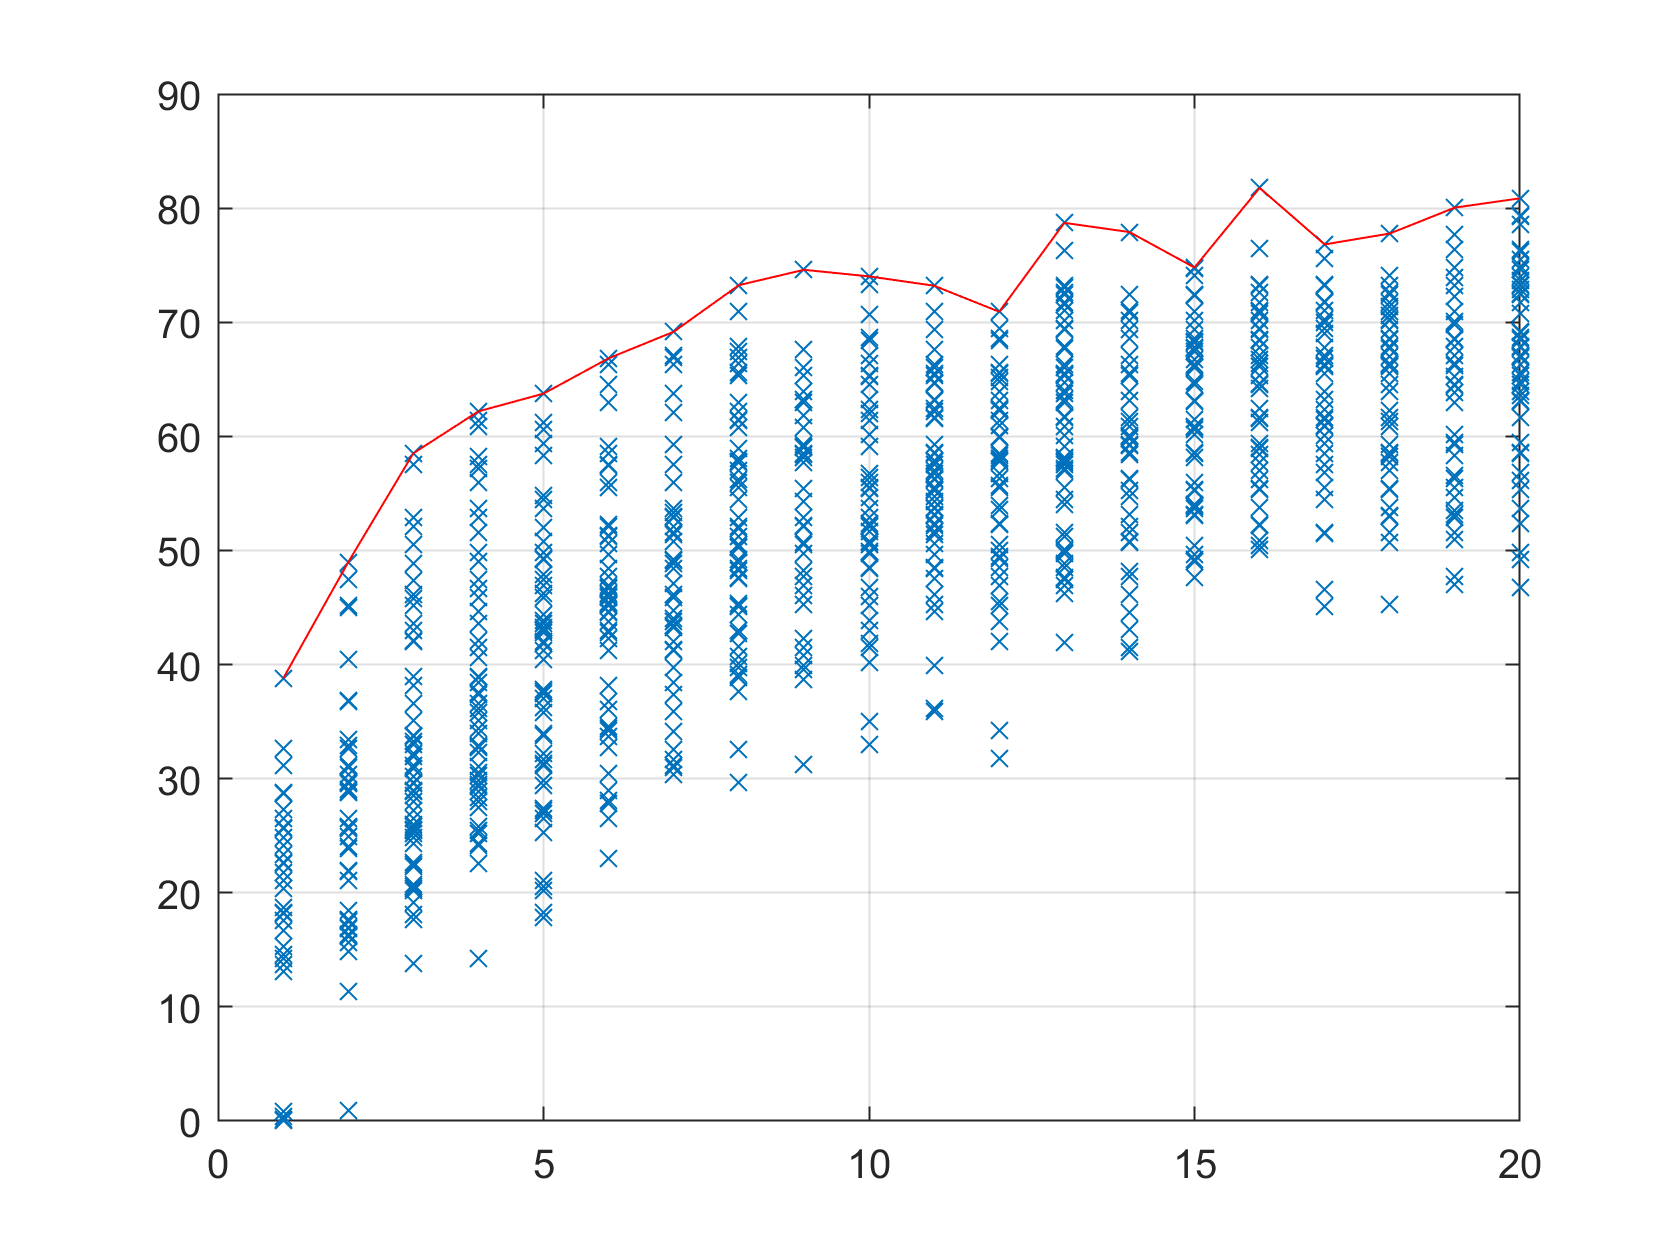

figure
plot(fx(:,1), fx(:,2),'x')
grid on
hold all
maxfx=[];
for i = 1:maxsensors
    maxfx(i,:)= [i max(fx(fx(:,1)==i,2))];
end
plot(maxfx(:,1), maxfx(:,2),'r-')

**Discussion: Is this a valid way of solving problems?**

**How can we solve this optimization problem?**

- Integer/Mixed Integer Quadradic Programming

- Evolutionary Optimization (Single-objective)

- Evolutionary Optimization (Multi-objective)

rng(2)
Nsensors = 5

Nsensors = 5

[Nsall, Nnodes] = size(Kall)

Nsall = 37152

Nnodes = 129

gafunc = @(x) calc_score(x,Kall,Nsall)

gafunc = function_handle with value:
    @(x)calc_score(x,Kall,Nsall)


[x,fval] = ga(gafunc, Nsensors,[],[],[],[],ones(Nsensors,1),Nnodes*ones(Nsensors,1));

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


sensors = round(x)

sensors =     46   125    84   101    15


sensorsID = G.getNodeNameID(sensors)

sensorsID = 1×5 cell array
    {'JUNCTION-45'}    {'JUNCTION-126'}    {'JUNCTION-83'}    {'JUNCTION-100'}    {'JUNCTION-14'}


score = -fval

score = 81.7695

Plot the location of the sensors

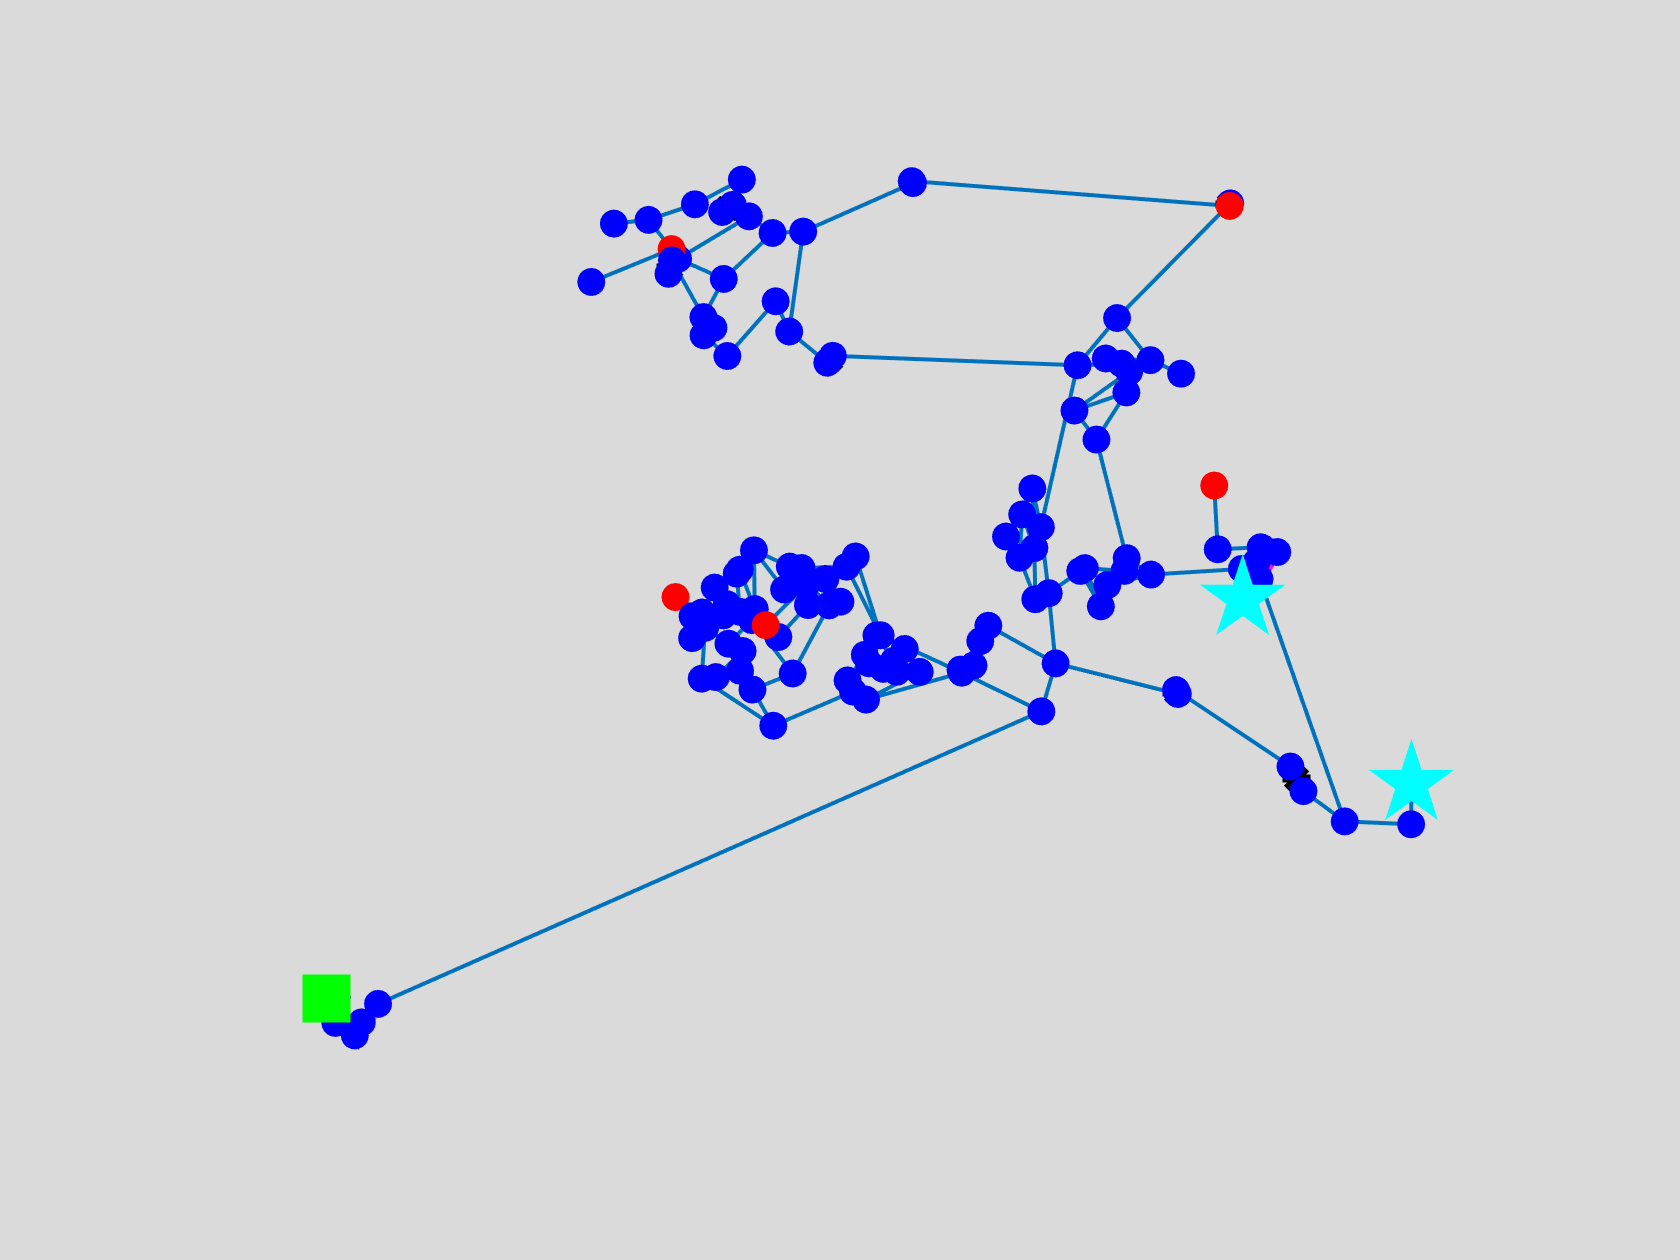

ans =   Axes with properties:

             XLim: [-2.5667e+03 2.8488e+04]
             YLim: [-1.3545e+03 1.4899e+04]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


G.plot('highlightnode',sensorsID)

**What happens when we have multiple objectives**? 

- Minimize detection time and maximize coverage

- No single optimal solution

- Need to compute a pareto front of solutions

% Table of all scenarios vs nodes, with flag = 1 
% if the contaminant is observed at that node 
load Kall.mat 
% Table of all scenarios vs nodes, detection time in minutes
load Tall.mat

**Solve the multi-objective optimization using the NSGA-II method**

rng(12)
Nsensors = 5

Nsensors = 5

[Nsall, Nnodes] = size(Kall)

Nsall = 37152

Nnodes = 129

gamultifunc = @(x) calc_score_multi(x,Kall,Nsall,Tall)

gamultifunc = function_handle with value:
    @(x)calc_score_multi(x,Kall,Nsall,Tall)


[x,fval] = gamultiobj(gamultifunc, Nsensors,[],[],[],[],ones(Nsensors,1),Nnodes*ones(Nsensors,1))

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


x =    34.0476   65.6212  121.8457   83.9429   18.3939
   34.0479   65.6212  121.8457   83.9405   18.3939
   34.1339   65.5698  121.8436   83.9412   18.3972
   34.0476   65.6212  121.8457   83.9428   18.3939
   34.0478   65.6212  121.8457   83.9413   18.3939
   34.0478   65.6212  121.8457   83.9423   18.3939
   12.6732   47.1764  116.9912   83.8686   16.3704
   12.6733   47.1767  116.9912   83.8686   16.3704
   34.0476   65.6212  121.8456   83.9428   18.3940
   34.1138   65.5810  121.8454   83.9420   18.3951


fval = 	1.0e+03 *

   -0.0725    0.7800
   -0.0725    0.7800
   -0.0725    0.7800
   -0.0725    0.7800
   -0.0725    0.7800
   -0.0725    0.7800
   -0.0779    1.0550
   -0.0779    1.0550
   -0.0725    0.7800
   -0.0725    0.7800


sensors = round(x)

sensors =     34    66   122    84    18
    34    66   122    84    18
    34    66   122    84    18
    34    66   122    84    18
    34    66   122    84    18
    34    66   122    84    18
    13    47   117    84    16
    13    47   117    84    16
    34    66   122    84    18
    34    66   122    84    18


**Plot the results and the Pareto Front**

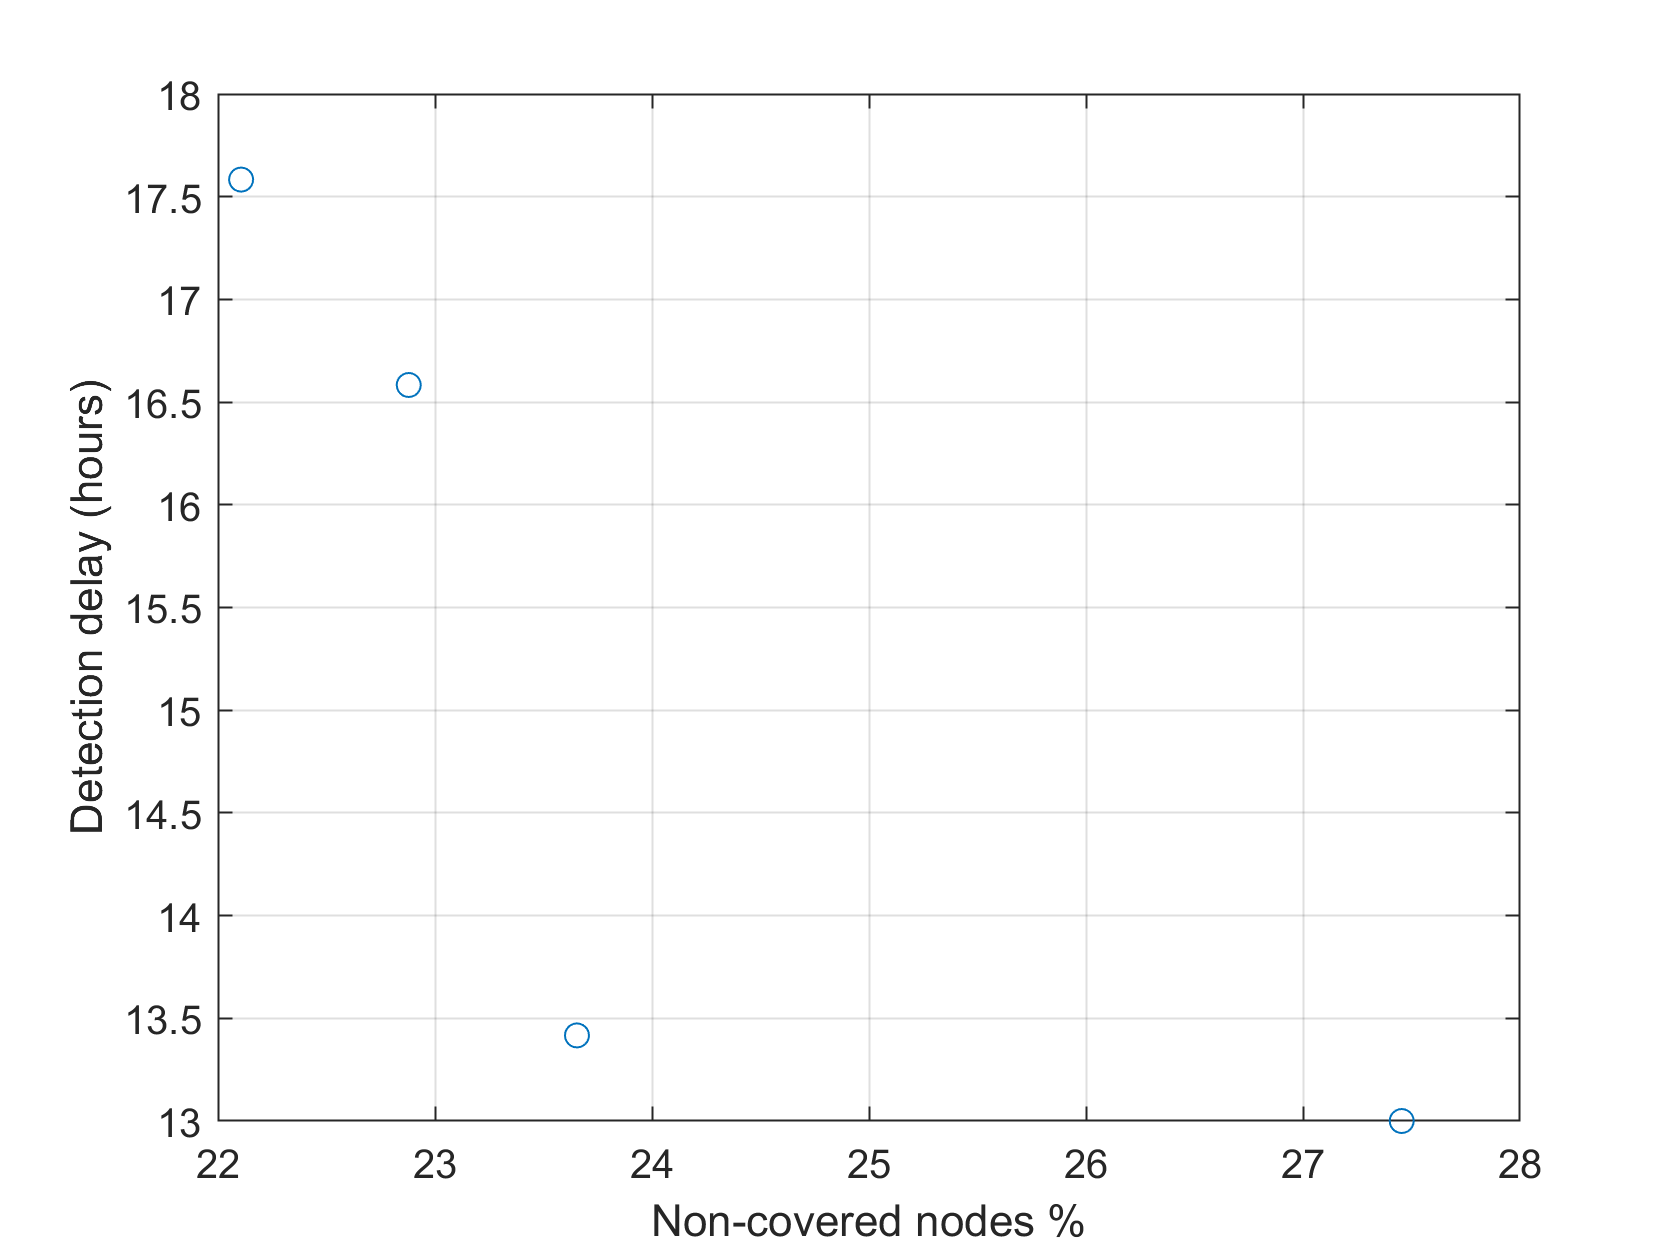

figure
plot(100+fval(:,1),fval(:,2)/60,'o')
grid on
xlabel('Non-covered nodes %')
ylabel('Detection delay (hours)')

**Function definitions**

Single objective function

function gafunc = calc_score(x, Kall, Nsall)
    gafunc = -sum(max(Kall(:,round(x)),[],2))/Nsall*100;
end

Multi-objective function

function gamultifunc = calc_score_multi(x, Kall, Nsall,Tall)
    gamultifunc(1) = -sum(max(Kall(:,round(x)),[],2))/Nsall*100;
    gamultifunc(2) = median(min(Tall(:,round(x)),[],2));
end